% clear


% load ryan4_data.mat
% load ryan4_model_SOH_RUL.mat


generate_model = false

generate_model = logical
   0


save_model = false

save_model = logical
   0



% generate_model = true
% save_model = true 

% generate_model = false
if generate_model == false
    load ryan4_model_SOH_RUL.mat
end

# 필요한 데이타 로딩

%% https://kr.mathworks.com/help/matlab/ref/load.html

load('ryan4_data.mat','x_trainValid_Ic_SOH')
load('ryan4_data.mat','x_test_IcSoh_RUL')

load('ryan4_data.mat','xmin_Ic_SOH')
load('ryan4_data.mat','xrate_Ic_SOH')
load('ryan4_data.mat','xnorm_Ic_SOH')

load('ryan4_data.mat','x_trainValid_Vd_SOH')
load('ryan4_data.mat','x_test_VdSoh_RUL')

load('ryan4_data.mat','xmin_Vd_SOH')
load('ryan4_data.mat','xrate_Vd_SOH')
load('ryan4_data.mat','xnorm_SOH')


load('ryan4_data.mat','ynorm_SOH')
load('ryan4_data.mat','ymin_RUL')
load('ryan4_data.mat','yrate_RUL')

load('ryan4_data.mat','y_trainValid_SOH')
load('ryan4_data.mat','Y_trainValid_RUL')
load('ryan4_data.mat','y_test_RUL')
load('ryan4_data.mat','Y_test_RUL')
load('ryan4_data.mat','ymin_RUL')
load('ryan4_data.mat','yrate_RUL')


load('ryan4_data.mat','idxTrainAll')
load('ryan4_data.mat','idxValidAll')
load('ryan4_data.mat','idxTestAll')

load('ryan4_data.mat','idxTrain')
load('ryan4_data.mat','idxValid')
load('ryan4_data.mat','idxTest')



% 같은 SOH라도 입력패턴에 따라 SOH은 변경된다.
% 입력패턴만으로 SOH을 예측하기 힘들다.
% 현재 CNN / LSTM 을 입력패턴, 출력패턴으로 하는 것은 의미가 없는 것 같다.
% CNN / LSTM 에서는 개별 입력/출력 패턴이 아닌 전체 사이클이 입력되어야 한다.

% 선형회귀도 전제 사이클 입력에 따른 출력이 표현이 가능할까? 
% 모든 데이타가 합쳐지면 그냥 전체 데이타의 평균일 뿐이다. 오차도 매우 커질수 있다.

% 알고리즘
% SOH 를 예측한다.
% 입출력 패턴을 이용해서 SOH를 업데이트 한다.

% 선형회귀 
% 변수를 기존 Ic 나 Vd만 사용하는 것이 아니고 SOH 까지 넣어서 RUL을 생성한다.



% input _VdSohRul
% x_trainValid_Ic_SOH 
% y_trainValid_SOH
% 
% output 
% y_trainValid_RUL

x_trainValid_IcSoh_RUL = [x_trainValid_Ic_SOH y_trainValid_SOH]

x_trainValid_IcSoh_RUL =     0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4132    0.1976    0.1976    0.1115    0.0830    0.0830    0.9878
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4874    0.1976    0.1976    0.1110    0.0830    0.0830    0.9872
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4864    0.1976    0.1976    0.1111    0.0830    0.0830    0.9867
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4519    0.1976    0.1976    0.1100    0.0830    0.0830    0.9861
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5869    0.5870    0.5870 

x_trainValid_VdSoh_RUL = [x_trainValid_Vd_SOH y_trainValid_SOH]

x_trainValid_VdSoh_RUL =     0.9175    0.8739    0.8637    0.8559    0.8482    0.8400    0.8309    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7076    0.6493    0.5376    0.2728    0.0009    0.0009    0.0009    0.9878
    0.9170    0.8736    0.8634    0.8556    0.8480    0.8397    0.8307    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7074    0.6490    0.5375    0.2720    0.0009    0.0009    0.0009    0.9872
    0.9177    0.8742    0.8638    0.8560    0.8483    0.8400    0.8310    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7075    0.6489    0.5365    0.2698    0.0009    0.0010    0.0010    0.9867
    0.9173    0.8737    0.8635    0.8558    0.8481    0.8398    0.8308    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7072    0.6486    0.5365    0.2662    0.0011    0.0013    0.0013    0.9861
    0.9172    0.8736    0.8635    0.8557    0.8480    0.8398    0.8308    0.8211    0.8106    0.7988    0.7847    0.7669    0.7428 

x_test_IcSoh_RUL = [x_test_Ic_RUL y_test_SOH]

x_test_IcSoh_RUL =     0.7703    0.7703    0.7702    0.7703    0.7702    0.7703    0.7702    0.5641    0.4266    0.4266    0.4266    0.4266    0.4266    0.4267    0.3269    0.1976    0.1976    0.1103    0.0830    0.0830    0.9869
    0.7703    0.7703    0.7702    0.7702    0.7702    0.7703    0.7702    0.5641    0.4266    0.4266    0.4266    0.4266    0.4266    0.4266    0.3266    0.1976    0.1976    0.1093    0.0830    0.0830    0.9861
    0.7702    0.7702    0.7703    0.7703    0.7703    0.7702    0.7703    0.5641    0.4266    0.4266    0.4266    0.4266    0.4267    0.4266    0.3265    0.1976    0.1976    0.1093    0.0830    0.0830    0.9852
    0.7703    0.7703    0.7702    0.7702    0.7703    0.7703    0.7703    0.5641    0.4267    0.4266    0.4266    0.4266    0.4266    0.4266    0.3267    0.1976    0.1976    0.1087    0.0830    0.0830    0.9843
    0.7703    0.7703    0.7703    0.7703    0.7703    0.7702    0.7702    0.5641    0.4267    0.4266    0.4266    0.4266    0.4266    0.4

x_test_VdSoh_RUL = [x_test_Vd_RUL y_test_SOH]

x_test_VdSoh_RUL =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011    0.9869
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008    0.9861
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011    0.9852
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009    0.9843
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7


% x_trainValid_IcSoh_RUL = [x_trainValid_Ic_SOH repmat(y_trainValid_SOH,1,20)]
% x_trainValid_VdSoh_RUL = [x_trainValid_Vd_SOH repmat(y_trainValid_SOH,1,20)]
% x_test_IcSoh_RUL = [x_test_Ic_RUL repmat(y_test_SOH,1,20)]
% x_test_VdSoh_RUL = [x_test_Vd_RUL repmat(y_test_SOH,1,20)]

# 선형회귀 - 모델 생성


%% https://kr.mathworks.com/help/matlab/ref/load.html
% load('ryan4_data.mat','x_trainValid_IcSohRulFull_SOH','x_trainValid_Ic_SOH','y_trainValid_Ic_SOH')

if generate_model
    tic
    mdl_Linear_IcSohRul = fitlm(x_trainValid_IcSoh_RUL,y_trainValid_RUL)
    toc 
    
    tic
    mdl_Linear_VdSohRul = fitlm(x_trainValid_VdSoh_RUL,y_trainValid_RUL)
    toc

    ryan4_model_SOH_RUL_desc = "ryan4_model_SOH_RUL_desc"
    %save('ryan4_model_SOH_RUL.mat','ryan4_model_SOH_RUL_desc' )
    save('ryan4_model_SOH_RUL.mat','mdl_Linear_IcSohRul' ,'-append')
    save('ryan4_model_SOH_RUL.mat','mdl_Linear_VdSohRul' ,'-append')
end

# 선형회귀 - 예측 - Ic (20)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

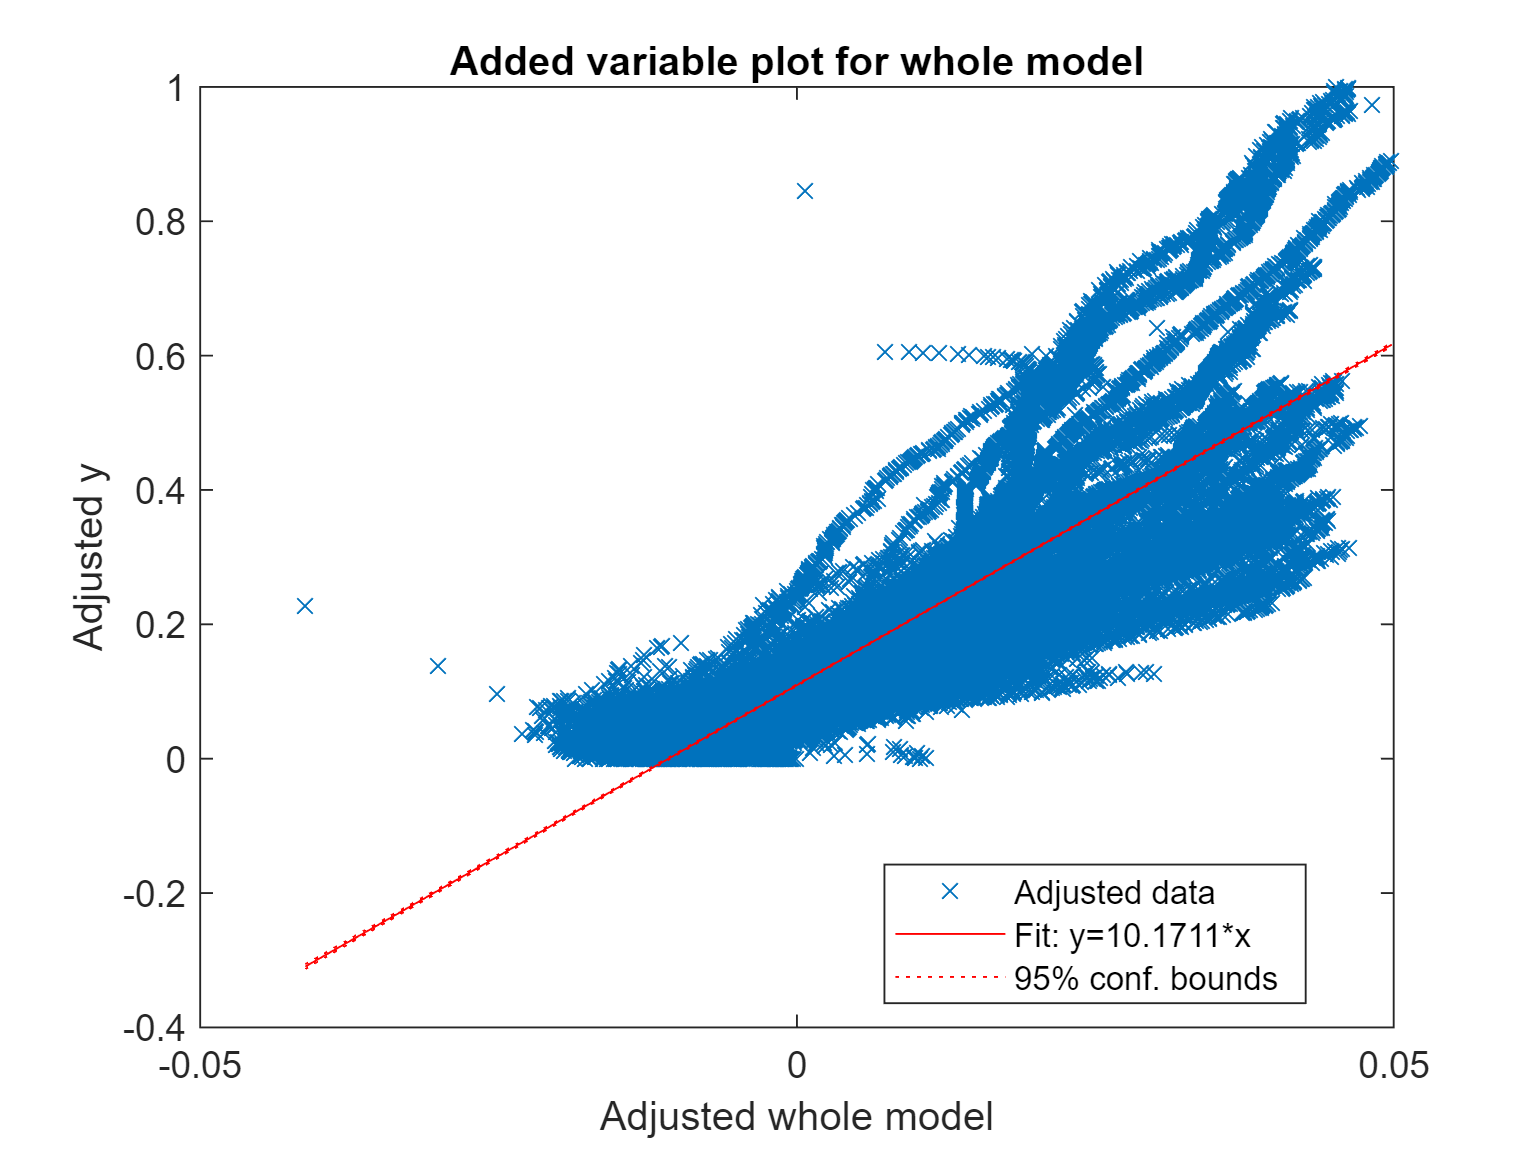

% coeff_IcSohRul = mdl_Linear_IcSohRul.Coefficients.Estimate;
% coeff_IcSohRul'
% x_trainValid_IcSoh_RUL(1,:)
% yhat_trainValid_IcSohRul = x_trainValid_IcSoh_RUL*coeff_IcSohRul(2:21)+coeff_IcSohRul(1);
% yhat_trainValid_IcSohRul'

% figure
% hold on
% plot(y_trainValid_RUL,yhat_trainValid_IcSohRul,'x')
% xlabel("Observed RUL")
% ylabel("Predicted RUL")
% hold off
% title 'Normalized'


figure
plot(mdl_Linear_IcSohRul)

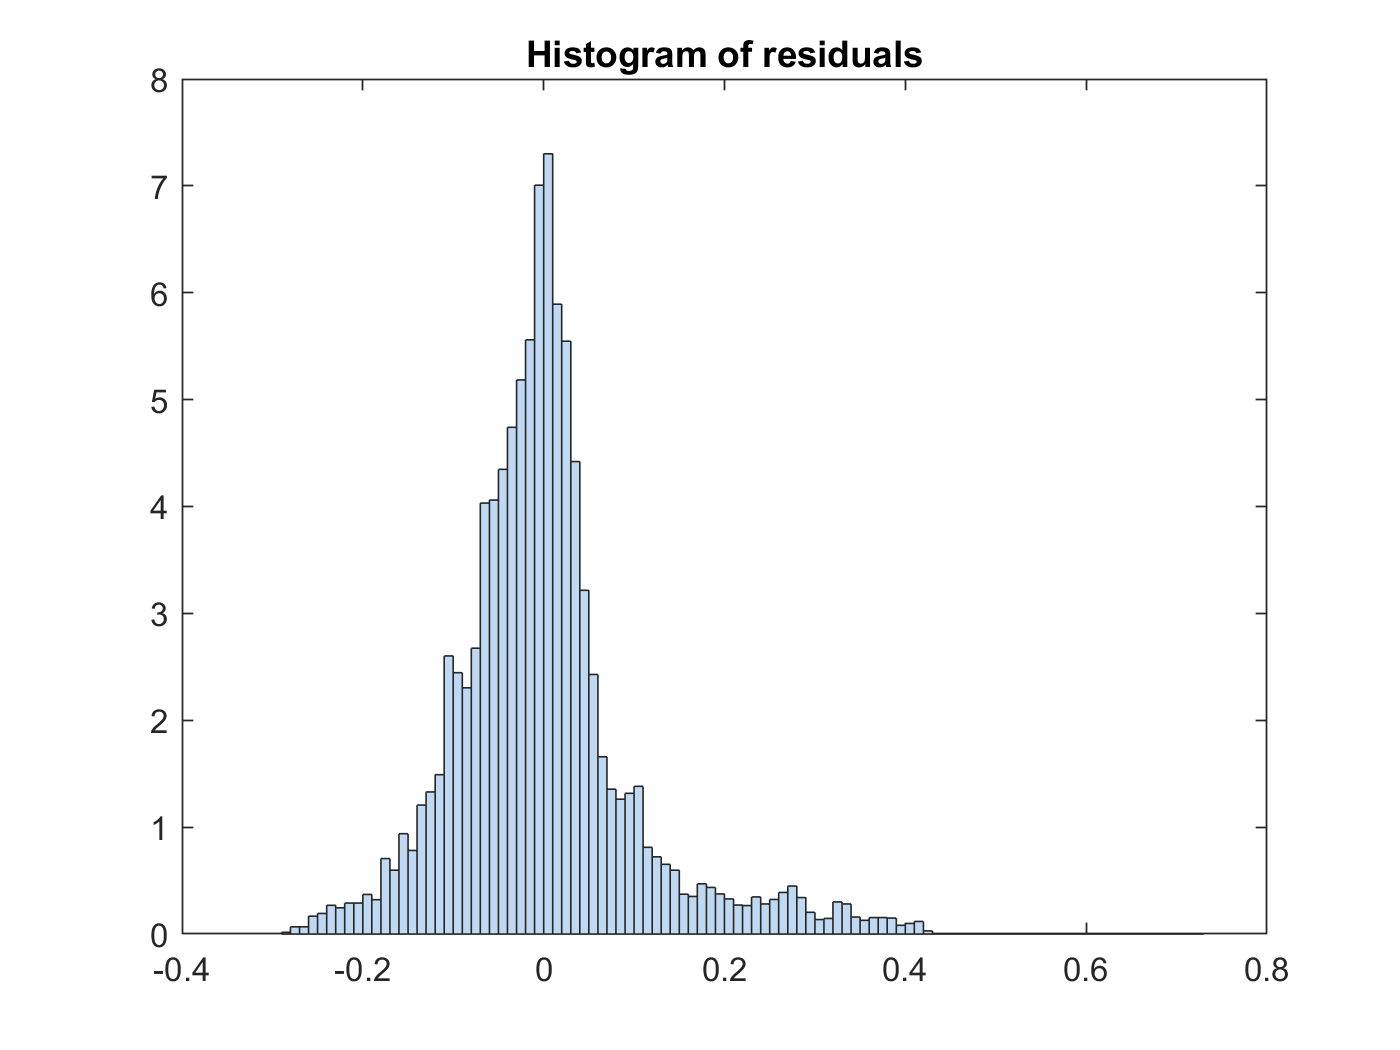

plotResiduals(mdl_Linear_IcSohRul)


figure
yfit_trainValid_IcSohRul = predict(mdl_Linear_IcSohRul,x_trainValid_IcSoh_RUL);
yfit_trainValid_IcSohRul'

ans =     0.3950    0.4675    0.4679    0.4238    0.4183    0.4548    0.4080    0.4504    0.3823    0.3793    0.4115    0.4441    0.4453    0.3868    0.3769    0.4369    0.4361    0.3610    0.4309    0.4326    0.4372    0.4374    0.3511    0.4324    0.4245    0.4200    0.3459    0.4132    0.3522    0.4114    0.4099    0.4067    0.4039    0.4038    0.3770    0.4013    0.3983    0.3975    0.3958    0.3445    0.3918    0.4171    0.3402    0.3903    0.3868    0.3944    0.3856    0.3167    0.3843    0.3348


yfit_test_IcSohRul = predict(mdl_Linear_IcSohRul,x_test_IcSoh_RUL);
yfit_test_IcSohRul'

ans =     0.3525    0.3450    0.3449    0.3408    0.3391    0.3339    0.3331    0.3312    0.3272    0.3247    0.3224    0.3167    0.3141    0.3139    0.3143    0.3114    0.3087    0.3080    0.3617    0.3588    0.3016    0.3053    0.3076    0.3648    0.3101    0.3095    0.3624    0.3039    0.2997    0.2929    0.2864    0.2823    0.2814    0.2799    0.2775    0.2759    0.2741    0.2725    0.2693    0.2694    0.2654    0.2672    0.2648    0.2627    0.2618    0.2604    0.2597    0.3130    0.2552    0.2546



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274


Yfit_trainValid_IcSohRul = yfit_trainValid_IcSohRul * yrate_RUL + ymin_RUL;
Yfit_test_IcSohRul = yfit_test_IcSohRul * yrate_RUL + ymin_RUL;

MAE_IcSohRul = mean(abs(Yfit_trainValid_IcSohRul-Y_trainValid_RUL))

MAE_IcSohRul = 81.3417

adjMAE_IcSohRul = MAE_IcSohRul/range(Y_trainValid_RUL)

adjMAE_IcSohRul = 0.0695

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcSohRul)'    % Errors

ans =   -35.1277 -121.0257 -122.4742  -71.8861  -66.4404 -110.1138  -56.3803 -107.0186  -28.2966  -25.7643  -64.4452 -103.5751 -106.0070  -38.5652  -27.9992  -99.1317  -99.1926  -12.3723  -95.1402  -98.1341 -104.5073 -105.7463   -5.7745 -101.9405  -93.6671  -89.4454   -3.6826  -83.4251  -13.0824  -83.2828  -82.6266  -79.8166  -77.5770  -78.4834  -48.0894  -77.4863  -75.0585  -75.0175  -74.1195  -15.0825  -71.3893 -101.9819  -13.0793  -72.6402  -69.5738  -79.4552  -70.1946    9.4692  -70.5812  -13.7664


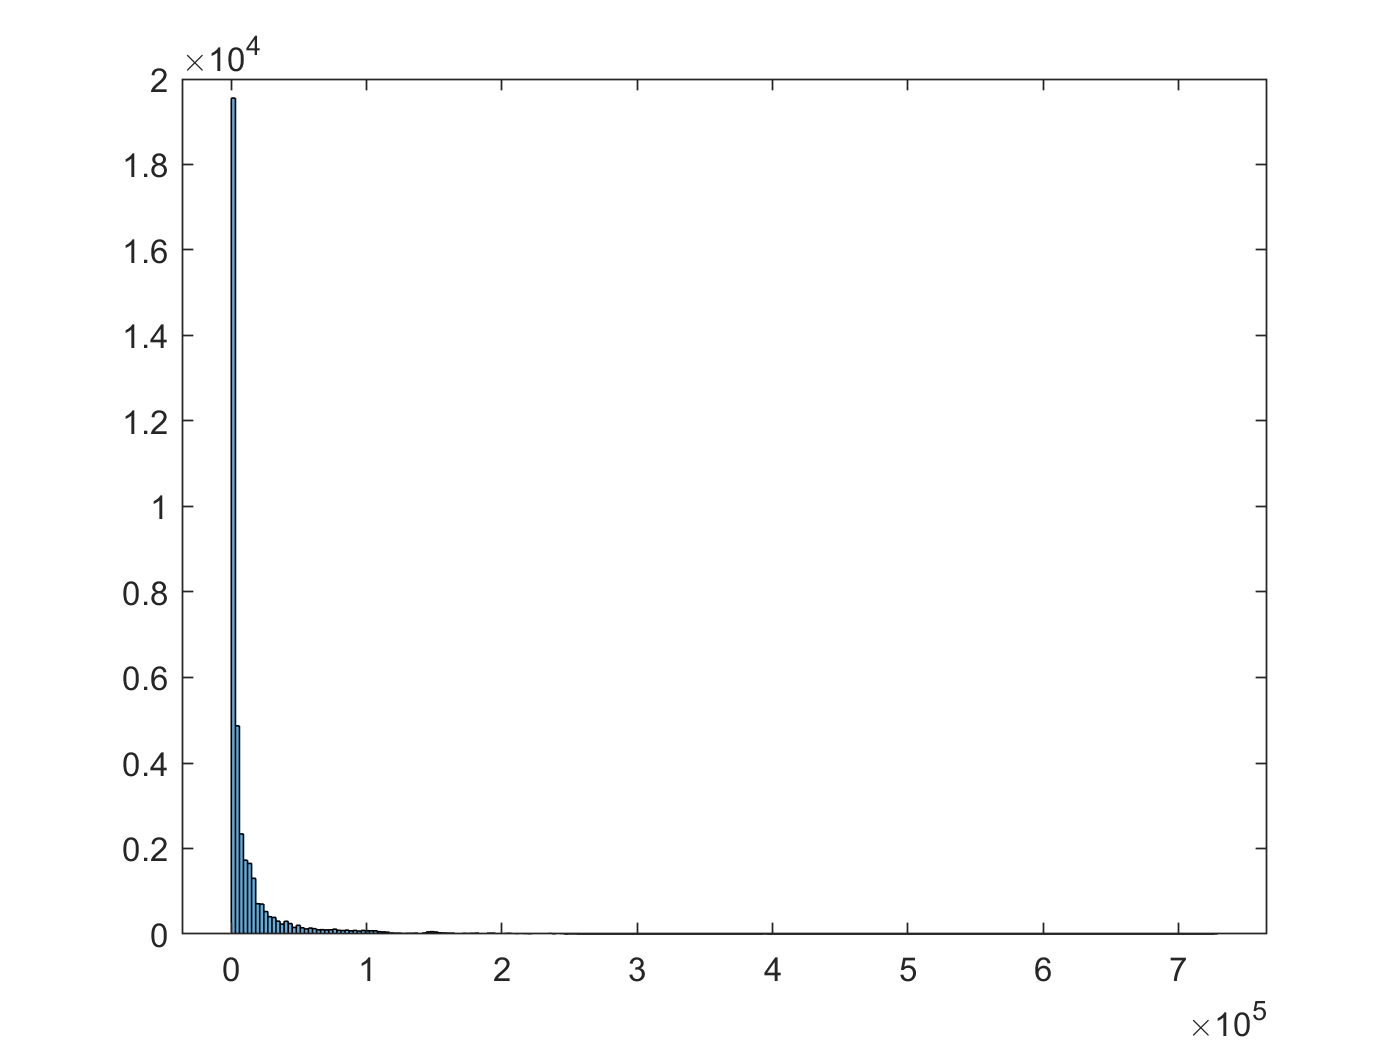

(Y_trainValid_RUL - Yfit_trainValid_IcSohRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcSohRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcSohRul).^2);   % Mean Squared Error
RMSE_trainValid_IcSohRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcSohRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcSohRul = 117.8511


RMSE_test_IcSohRul = sqrt(mean((Y_test_RUL - Yfit_test_IcSohRul).^2))

RMSE_test_IcSohRul = 121.6697

Y_test_RUL - Yfit_test_IcSohRul

ans =   -97.4664
  -89.6143
  -90.5850
  -86.7825
  -85.7348
  -80.7056
  -80.7471
  -79.5305
  -75.8331
  -73.8685


Y_test_diff_IcSohRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcSohRul))

Y_test_diff_IcSohRul = 1.0e+03 *

    0.3160   -0.0975
    0.3150   -0.0896
    0.3140   -0.0906
    0.3130   -0.0868
    0.3120   -0.0857
    0.3110   -0.0807
    0.3100   -0.0807
    0.3090   -0.0795
    0.3080   -0.0758
    0.3070   -0.0739


Y_test_diff_percentage_IcSohRul = abs(Y_test_RUL-Yfit_test_IcSohRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcSohRul = 1.0e+04 *

    0.0031
    0.0028
    0.0029
    0.0028
    0.0027
    0.0026
    0.0026
    0.0026
    0.0025
    0.0024


Y_test_diff_percentage_avg_IcSohRul = sum(Y_test_diff_percentage_IcSohRul)/length(Y_test_diff_percentage_IcSohRul)

Y_test_diff_percentage_avg_IcSohRul = 96.0229

Y_trainValid_diff_IcSohRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcSohRul))

Y_trainValid_diff_IcSohRul = 1.0e+03 *

    0.4280   -0.0351
    0.4270   -0.1210
    0.4260   -0.1225
    0.4250   -0.0719
    0.4240   -0.0664
    0.4230   -0.1101
    0.4220   -0.0564
    0.4210   -0.1070
    0.4200   -0.0283
    0.4190   -0.0258


Y_trainValid_diff_percentage_IcSohRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcSohRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcSohRul = 1.0e+04 *

    0.0008
    0.0028
    0.0029
    0.0017
    0.0016
    0.0026
    0.0013
    0.0025
    0.0007
    0.0006


Y_trainValid_diff_percentage_avg_IcSohRul = sum(Y_trainValid_diff_percentage_IcSohRul)/length(Y_trainValid_diff_percentage_IcSohRul)

Y_trainValid_diff_percentage_avg_IcSohRul = 90.7965

num = 1:length(Y_trainValid_RUL);


result = horzcat(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcSohRul),Y_trainValid_diff_percentage_IcSohRul);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+04 *

    0.0001    0.0428   -0.0035    0.0008
    0.0002    0.0427   -0.0121    0.0028
    0.0003    0.0426   -0.0122    0.0029
    0.0004    0.0425   -0.0072    0.0017
    0.0005    0.0424   -0.0066    0.0016
    0.0006    0.0423   -0.0110    0.0026
    0.0007    0.0422   -0.0056    0.0013
    0.0008    0.0421   -0.0107    0.0025
    0.0009    0.0420   -0.0028    0.0007
    0.0010    0.0419   -0.0026    0.0006


result_mdl_Linear_IcSohRul = table(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcSohRul),Y_trainValid_diff_percentage_IcSohRul);
result_mdl_Linear_IcSohRul.Properties.VariableNames = {'bat num','RUL','Error','APE'};
result_mdl_Linear_IcSohRul

result_mdl_Linear_IcSohRul = 38367×4 table
    bat num    RUL     Error      APE  
    _______    ___    _______    ______

       1       428    -35.128    8.2074
       2       427    -121.03    28.343
       3       426    -122.47     28.75
       4       425    -71.886    16.914
       5       424     -66.44     15.67
       6       423    -110.11    26.032
       7       422     -56.38     13.36
       8       421    -107.02     25.42
       9       420    -28.297    6.7373
      10       419    -25.764     6.149
      11       418    -64.445    15.418
      12       417    -103.58    24.838
      13       416    -106.01    25.482
      14       415    -38.565    9.2928
      15       414    -27.999    6.7631
      16       413    -99.132    24.003


result_mdl_Linear_IcSohRul_summary = table(RMSE_test_IcSohRul,Y_trainValid_diff_percentage_avg_IcSohRul);
result_mdl_Linear_IcSohRul_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_mdl_Linear_IcSohRul_summary 

result_mdl_Linear_IcSohRul_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    121.67    90.796


Linear_IcSohRul_rmse = RMSE_test_IcSohRul

Linear_IcSohRul_rmse = 121.6697

Linear_IcSohRul_mape = Y_trainValid_diff_percentage_avg_IcSohRul

Linear_IcSohRul_mape = 90.7965

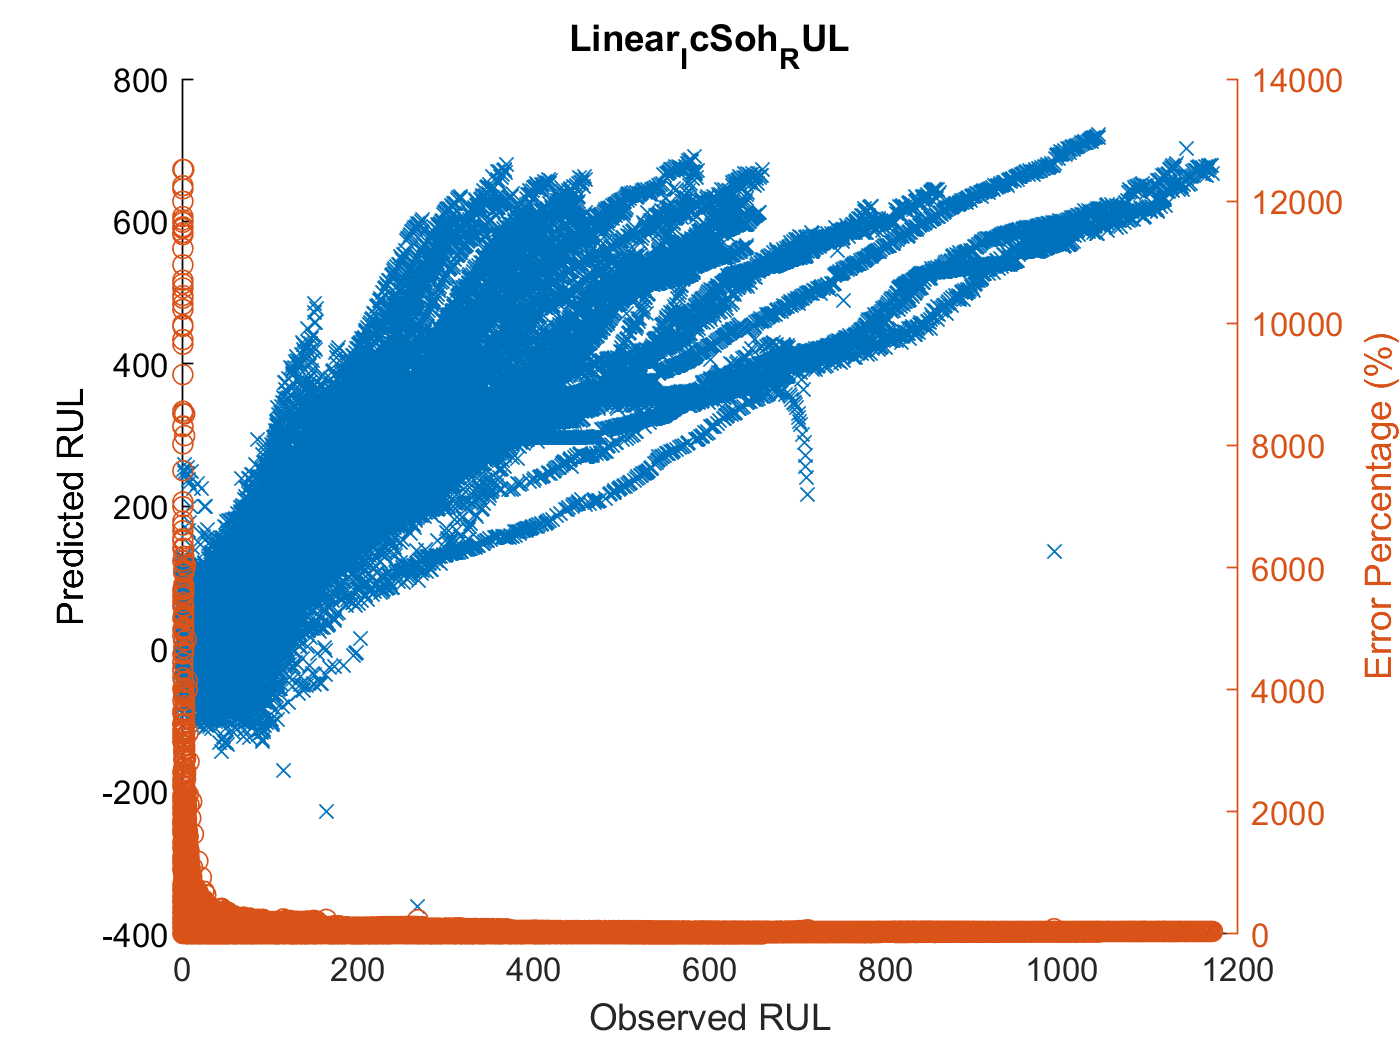

figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcSohRul,'o');

hold off
title 'Linear_IcSoh_RUL'

RMSE_test_IcSohRul

RMSE_test_IcSohRul = 121.6697

Y_trainValid_diff_percentage_avg_IcSohRul

Y_trainValid_diff_percentage_avg_IcSohRul = 90.7965

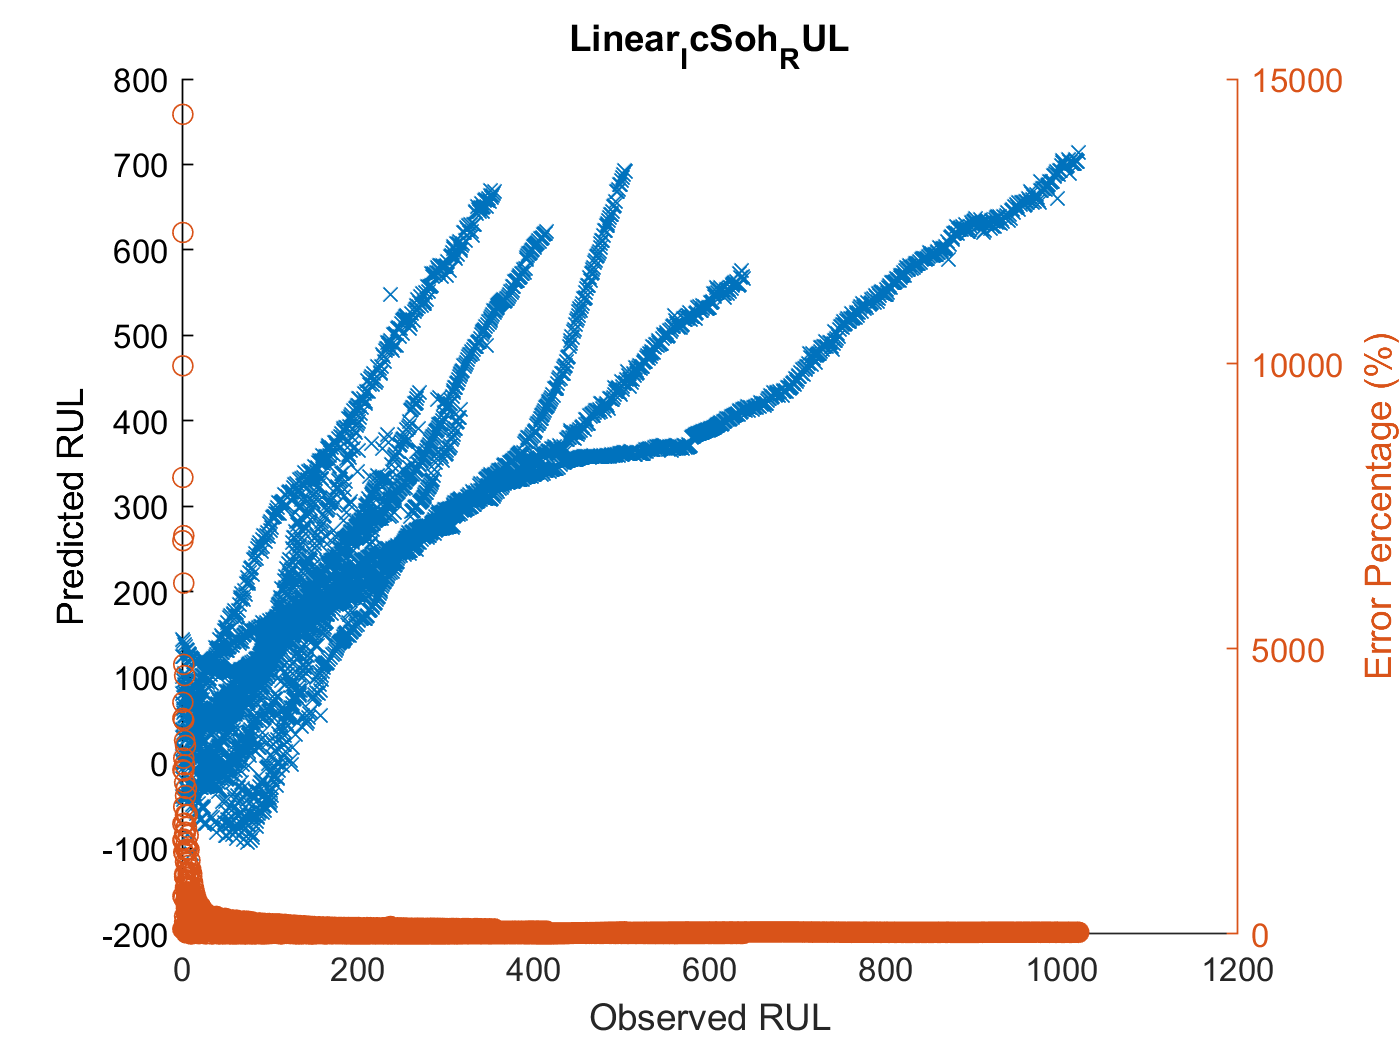


figure
hold on
plot(Y_test_RUL,Yfit_test_IcSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_RUL,Y_test_diff_percentage_IcSohRul,'o');

hold off
title 'Linear_IcSoh_RUL'

# 선형회귀 - 예측 - Vd (20)

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

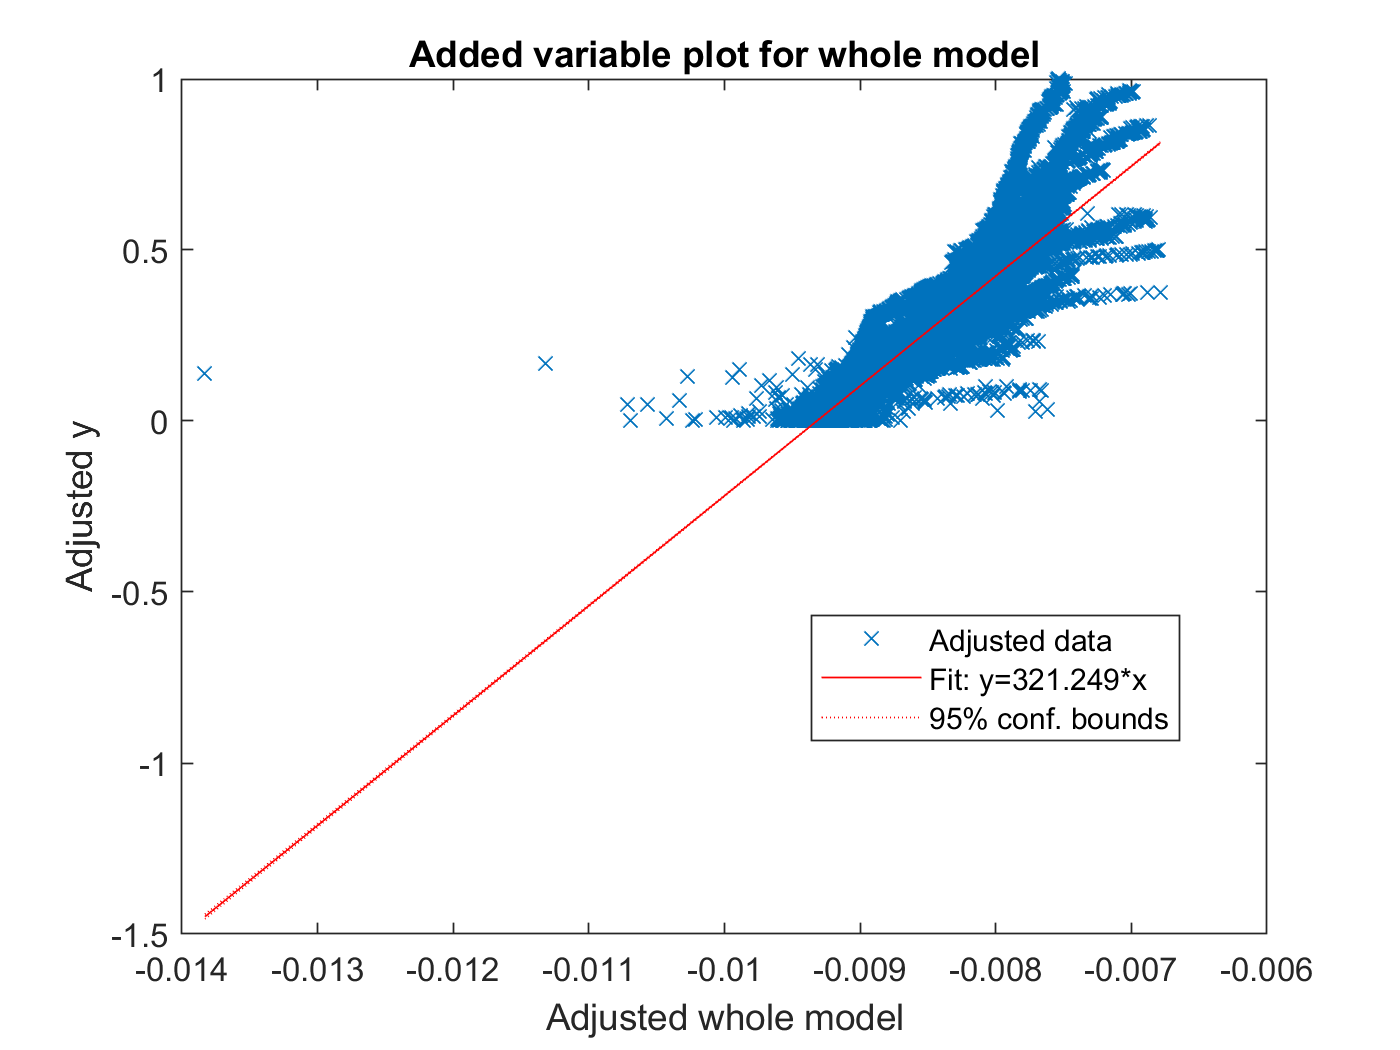

% coeff_VdSohRul = mdl_Linear_VdSohRul.Coefficients.Estimate;
% coeff_VdSohRul'
% x_trainValid_VdSoh_RUL(1,:)
% yhat_trainValid_VdSohRul = x_trainValid_VdSoh_RUL*coeff_VdSohRul(2:21)+coeff_VdSohRul(1);
% yhat_trainValid_VdSohRul'
% figure
% hold on
% plot(y_trainValid_RUL,yhat_trainValid_VdSohRul,'x')
% xlabel("Observed RUL")
% ylabel("Predicted RUL")
% hold off
% title 'Normalized'

figure
plot(mdl_Linear_VdSohRul)

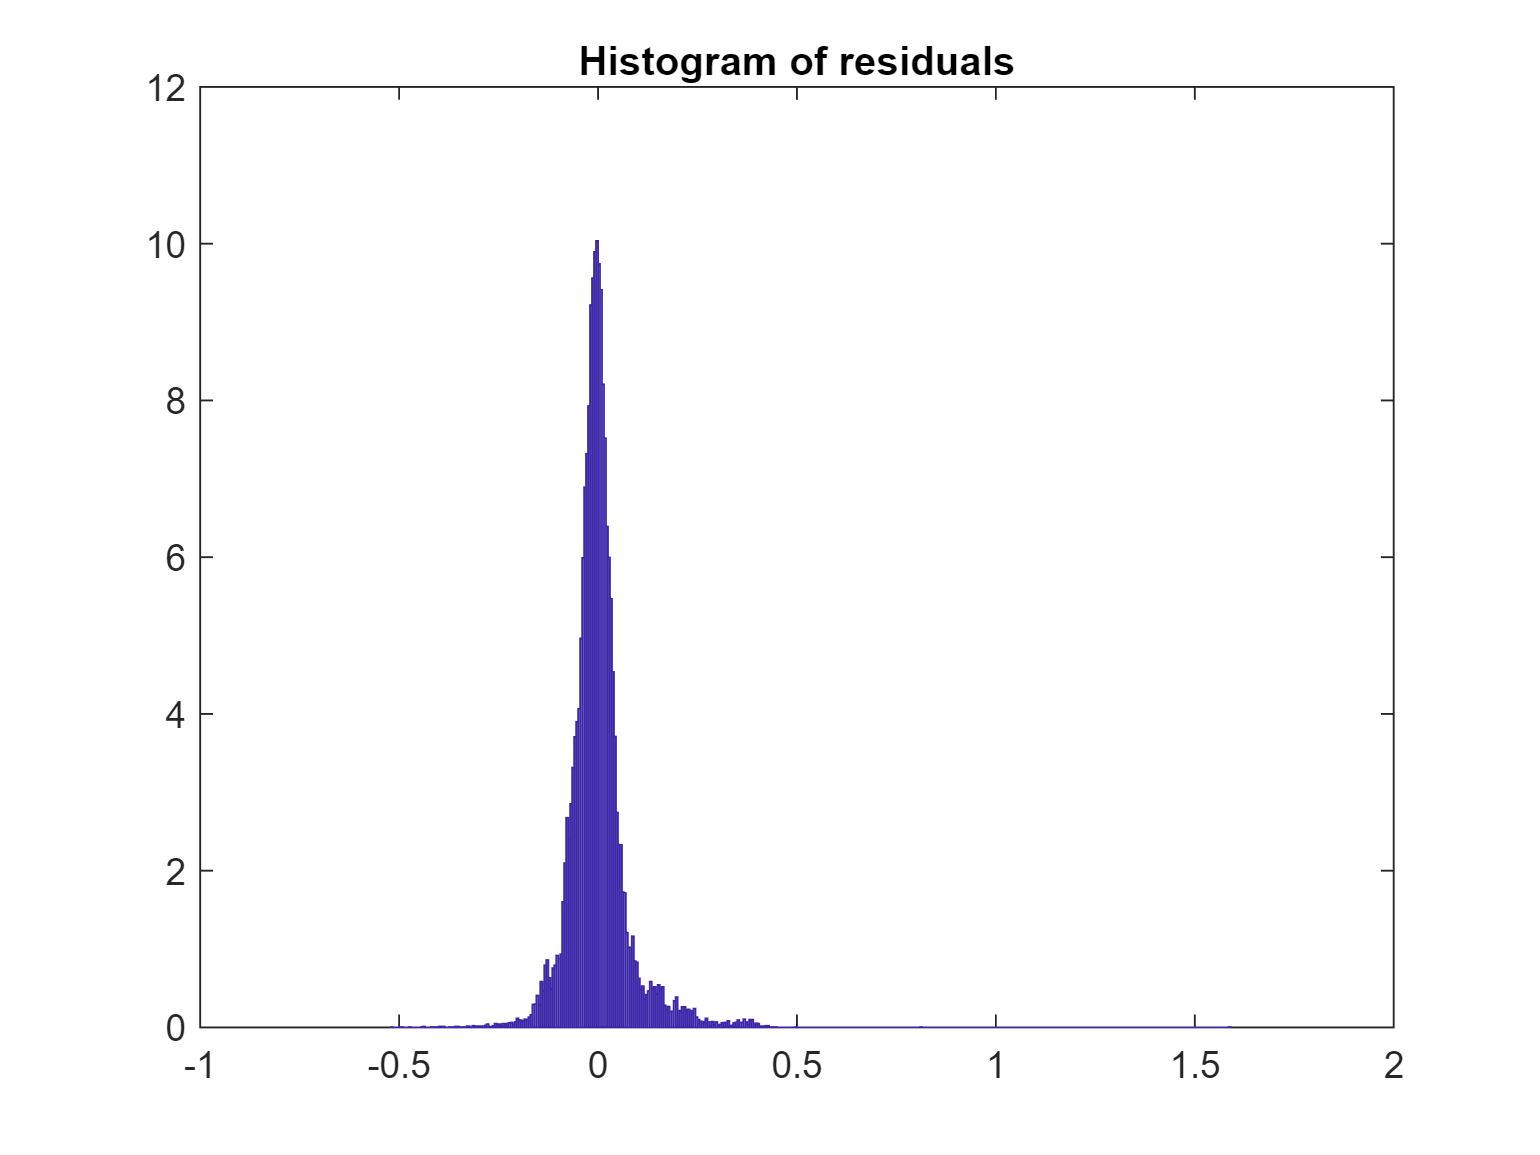

plotResiduals(mdl_Linear_VdSohRul)

figure
yfit_trainValid_VdSohRul = predict(mdl_Linear_VdSohRul,x_trainValid_VdSoh_RUL);
yfit_trainValid_VdSohRul'

ans =     0.3902    0.3978    0.3916    0.3862    0.3924    0.3922    0.3845    0.3890    0.3759    0.3740    0.3851    0.3866    0.3874    0.3841    0.3771    0.3845    0.3862    0.3750    0.3802    0.3887    0.3941    0.3900    0.3844    0.3804    0.3833    0.3755    0.3734    0.3671    0.3773    0.3740    0.3755    0.3707    0.3742    0.3720    0.3631    0.3696    0.3688    0.3630    0.3639    0.3625    0.3664    0.3666    0.3603    0.3709    0.3650    0.3565    0.3581    0.3594    0.3665    0.3656


yfit_test_VdSohRul = predict(mdl_Linear_VdSohRul,x_test_VdSoh_RUL);
yfit_test_VdSohRul'

ans =     0.3353    0.3389    0.3360    0.3278    0.3209    0.3254    0.3182    0.3321    0.3244    0.3254    0.3178    0.3145    0.3130    0.3223    0.3235    0.3195    0.3089    0.3142    0.3128    0.2970    0.3067    0.3170    0.3359    0.3293    0.3490    0.3420    0.3334    0.3341    0.3178    0.2992    0.2835    0.2942    0.2934    0.2861    0.2803    0.2841    0.2891    0.2785    0.2885    0.2805    0.2791    0.2727    0.2758    0.2707    0.2670    0.2644    0.2672    0.2625    0.2689    0.2751



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274


Yfit_trainValid_VdSohRul = yfit_trainValid_VdSohRul * yrate_RUL + ymin_RUL;
Yfit_test_VdSohRul = yfit_test_VdSohRul * yrate_RUL + ymin_RUL;

MAE_VdSohRul = mean(abs(Yfit_trainValid_VdSohRul-Y_trainValid_RUL))

MAE_VdSohRul = 54.3064

adjMAE_VdSohRul = MAE_VdSohRul/range(Y_trainValid_RUL)

adjMAE_VdSohRul = 0.0464

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_VdSohRul)'    % Errors

ans = 1.0e+03 *

   -0.0295   -0.0395   -0.0331   -0.0279   -0.0362   -0.0369   -0.0289   -0.0352   -0.0207   -0.0196   -0.0335   -0.0363   -0.0383   -0.0354   -0.0282   -0.0378   -0.0409   -0.0287   -0.0358   -0.0468   -0.0541   -0.0503   -0.0448   -0.0411   -0.0454   -0.0373   -0.0359   -0.0295   -0.0425   -0.0396   -0.0424   -0.0377   -0.0428   -0.0413   -0.0319   -0.0405   -0.0405   -0.0347   -0.0367   -0.0361   -0.0417   -0.0429   -0.0366   -0.0500   -0.0441   -0.0351   -0.0380   -0.0406   -0.0498   -0.0497


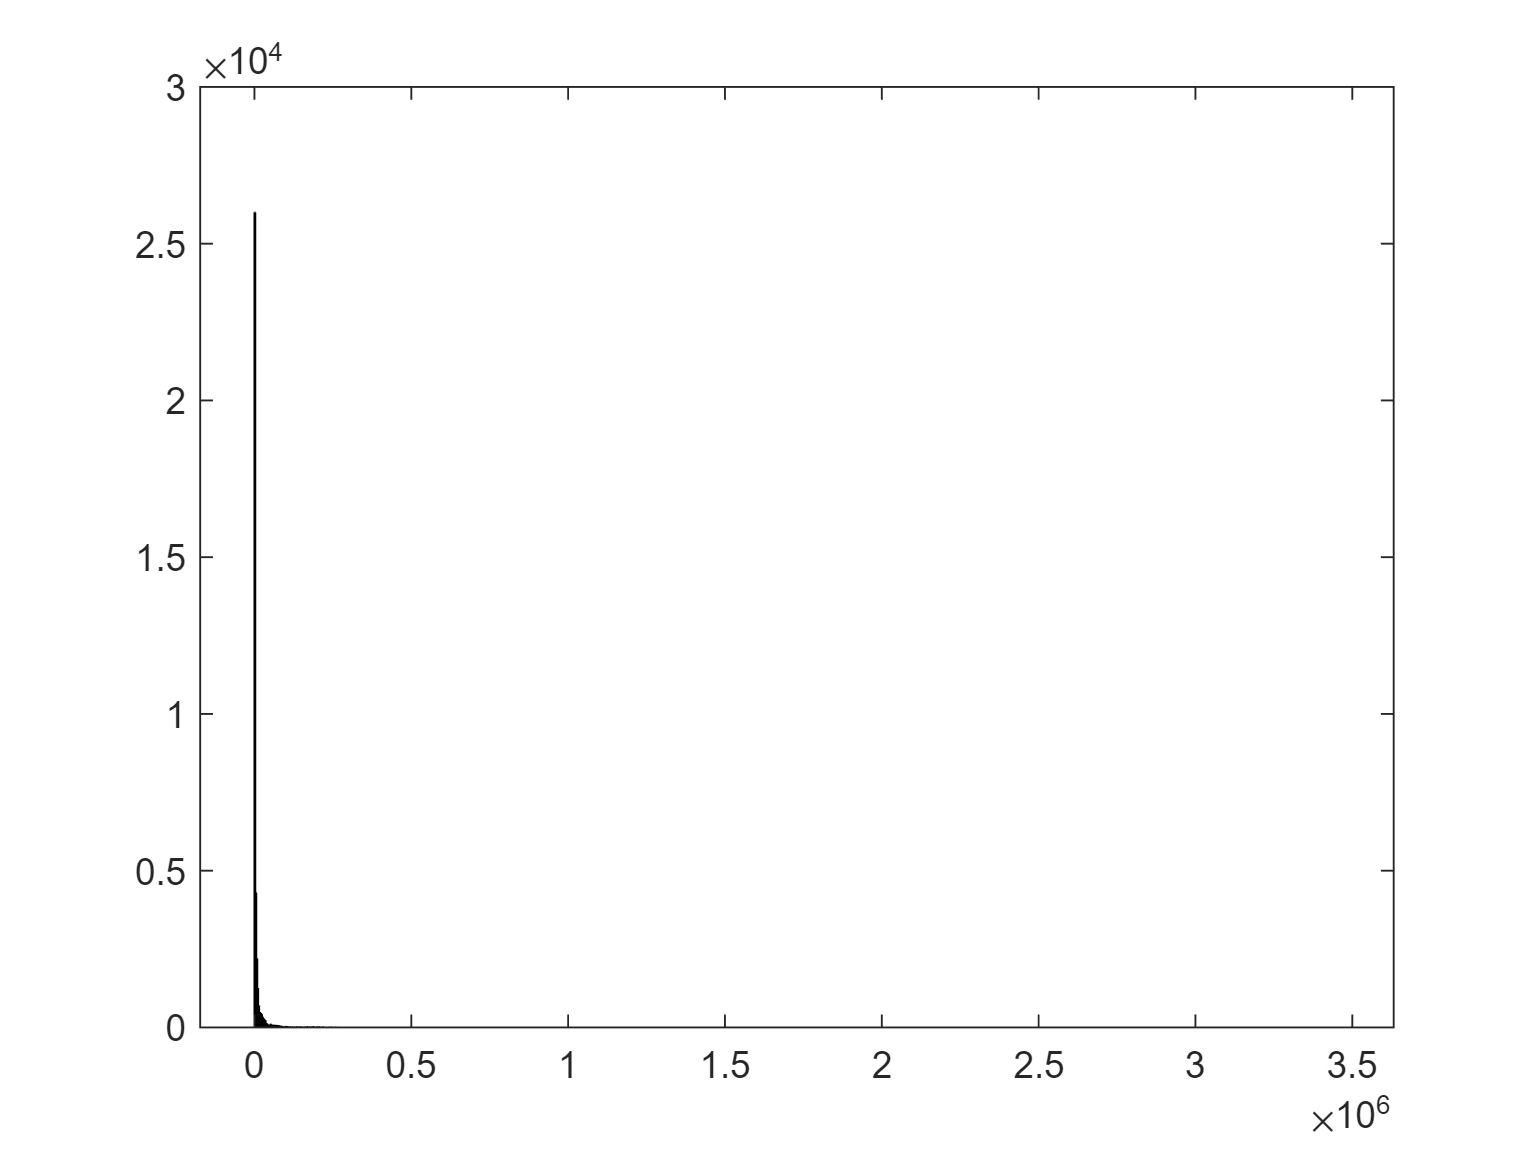

(Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2);   % Mean Squared Error
RMSE_trainValid_VdSohRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2))  % Root Mean Squared Error

RMSE_trainValid_VdSohRul = 84.0635


RMSE_test_VdSohRul = sqrt(mean((Y_test_RUL - Yfit_test_VdSohRul).^2))

RMSE_test_VdSohRul = 90.0701

Y_test_RUL - Yfit_test_VdSohRul

ans =   -77.2506
  -82.5434
  -80.0673
  -71.5589
  -64.4089
  -70.7059
  -63.2655
  -80.5186
  -72.5566
  -74.7661


Y_test_diff_VdSohRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_VdSohRul))

Y_test_diff_VdSohRul = 1.0e+03 *

    0.3160   -0.0773
    0.3150   -0.0825
    0.3140   -0.0801
    0.3130   -0.0716
    0.3120   -0.0644
    0.3110   -0.0707
    0.3100   -0.0633
    0.3090   -0.0805
    0.3080   -0.0726
    0.3070   -0.0748


Y_test_diff_percentage_VdSohRul = abs(Y_test_RUL-Yfit_test_VdSohRul)./Y_test_RUL.*100

Y_test_diff_percentage_VdSohRul = 1.0e+03 *

    0.0244
    0.0262
    0.0255
    0.0229
    0.0206
    0.0227
    0.0204
    0.0261
    0.0236
    0.0244


Y_test_diff_percentage_avg_VdSohRul = sum(Y_test_diff_percentage_VdSohRul)/length(Y_test_diff_percentage_VdSohRul)

Y_test_diff_percentage_avg_VdSohRul = 44.5178

Y_trainValid_diff_VdSohRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul))

Y_trainValid_diff_VdSohRul = 1.0e+03 *

    0.4280   -0.0295
    0.4270   -0.0395
    0.4260   -0.0331
    0.4250   -0.0279
    0.4240   -0.0362
    0.4230   -0.0369
    0.4220   -0.0289
    0.4210   -0.0352
    0.4200   -0.0207
    0.4190   -0.0196


Y_trainValid_diff_percentage_VdSohRul = abs(Y_trainValid_RUL-Yfit_trainValid_VdSohRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_VdSohRul = 1.0e+04 *

    0.0007
    0.0009
    0.0008
    0.0007
    0.0009
    0.0009
    0.0007
    0.0008
    0.0005
    0.0005


Y_trainValid_diff_percentage_avg_VdSohRul = sum(Y_trainValid_diff_percentage_VdSohRul)/length(Y_trainValid_diff_percentage_VdSohRul)

Y_trainValid_diff_percentage_avg_VdSohRul = 62.9835

num = 1:length(Y_trainValid_RUL);


result = horzcat(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul),Y_trainValid_diff_percentage_VdSohRul);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+04 *

    0.0001    0.0428   -0.0030    0.0007
    0.0002    0.0427   -0.0039    0.0009
    0.0003    0.0426   -0.0033    0.0008
    0.0004    0.0425   -0.0028    0.0007
    0.0005    0.0424   -0.0036    0.0009
    0.0006    0.0423   -0.0037    0.0009
    0.0007    0.0422   -0.0029    0.0007
    0.0008    0.0421   -0.0035    0.0008
    0.0009    0.0420   -0.0021    0.0005
    0.0010    0.0419   -0.0020    0.0005


result_mdl_Linear_VdSohRul = table(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul),Y_trainValid_diff_percentage_VdSohRul);
result_mdl_Linear_VdSohRul.Properties.VariableNames = {'bat num','RUL','Error','APE'};
result_mdl_Linear_VdSohRul

result_mdl_Linear_VdSohRul = 38367×4 table
    bat num    RUL     Error      APE  
    _______    ___    _______    ______

       1       428    -29.516    6.8963
       2       427    -39.459    9.2409
       3       426    -33.129    7.7768
       4       425      -27.9    6.5648
       5       424    -36.165    8.5295
       6       423    -36.867    8.7156
       7       422    -28.884    6.8445
       8       421    -35.178    8.3558
       9       420    -20.745    4.9393
      10       419     -19.57    4.6706
      11       418    -33.531    8.0217
      12       417    -36.287    8.7019
      13       416    -38.301     9.207
      14       415      -35.4    8.5301
      15       414    -28.206    6.8131
      16       413    -37.823    9.1581


result_mdl_Linear_VdSohRul_summary = table(RMSE_test_VdSohRul,Y_trainValid_diff_percentage_avg_VdSohRul);
result_mdl_Linear_VdSohRul_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_mdl_Linear_VdSohRul_summary 

result_mdl_Linear_VdSohRul_summary = 1×2 table
    RMSE      MAPE 
    _____    ______

    90.07    62.983


Linear_VdSohRul_rmse = RMSE_test_VdSohRul

Linear_VdSohRul_rmse = 90.0701

Linear_VdSohRul_mape = Y_trainValid_diff_percentage_avg_VdSohRul

Linear_VdSohRul_mape = 62.9835

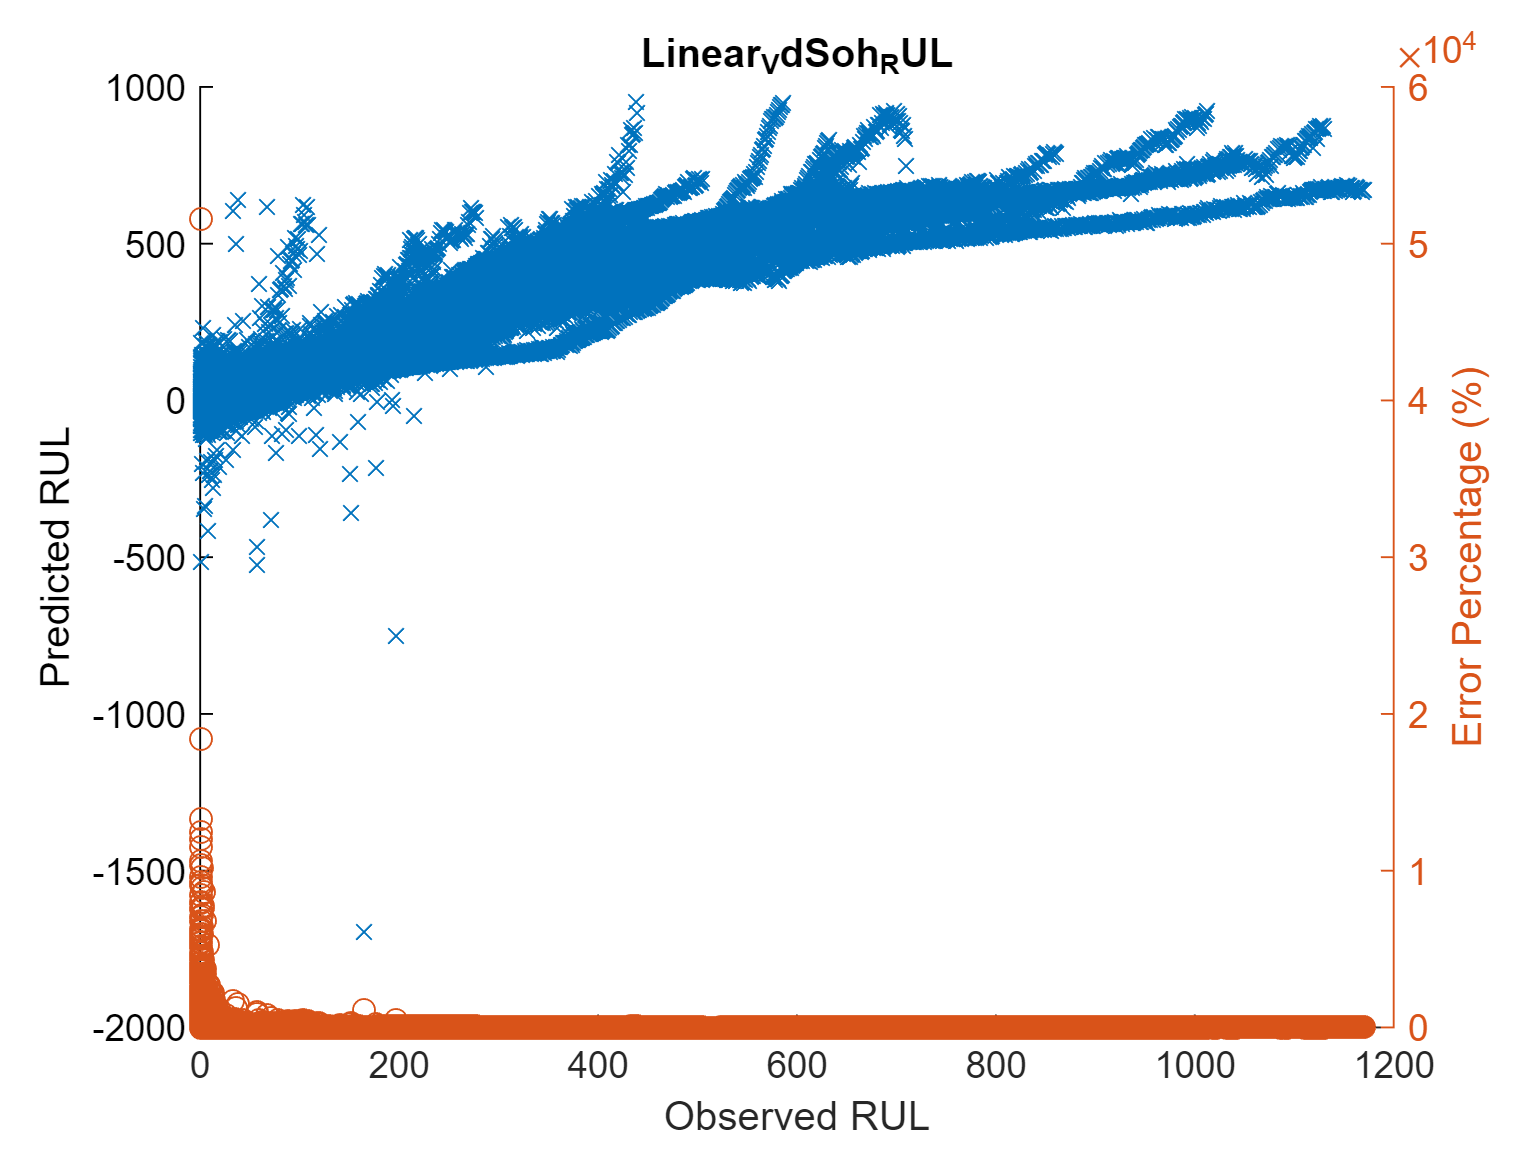

figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_VdSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_VdSohRul,'o');

hold off
title 'Linear_VdSoh_RUL'

RMSE_test_VdSohRul

RMSE_test_VdSohRul = 90.0701

Y_trainValid_diff_percentage_avg_VdSohRul

Y_trainValid_diff_percentage_avg_VdSohRul = 62.9835

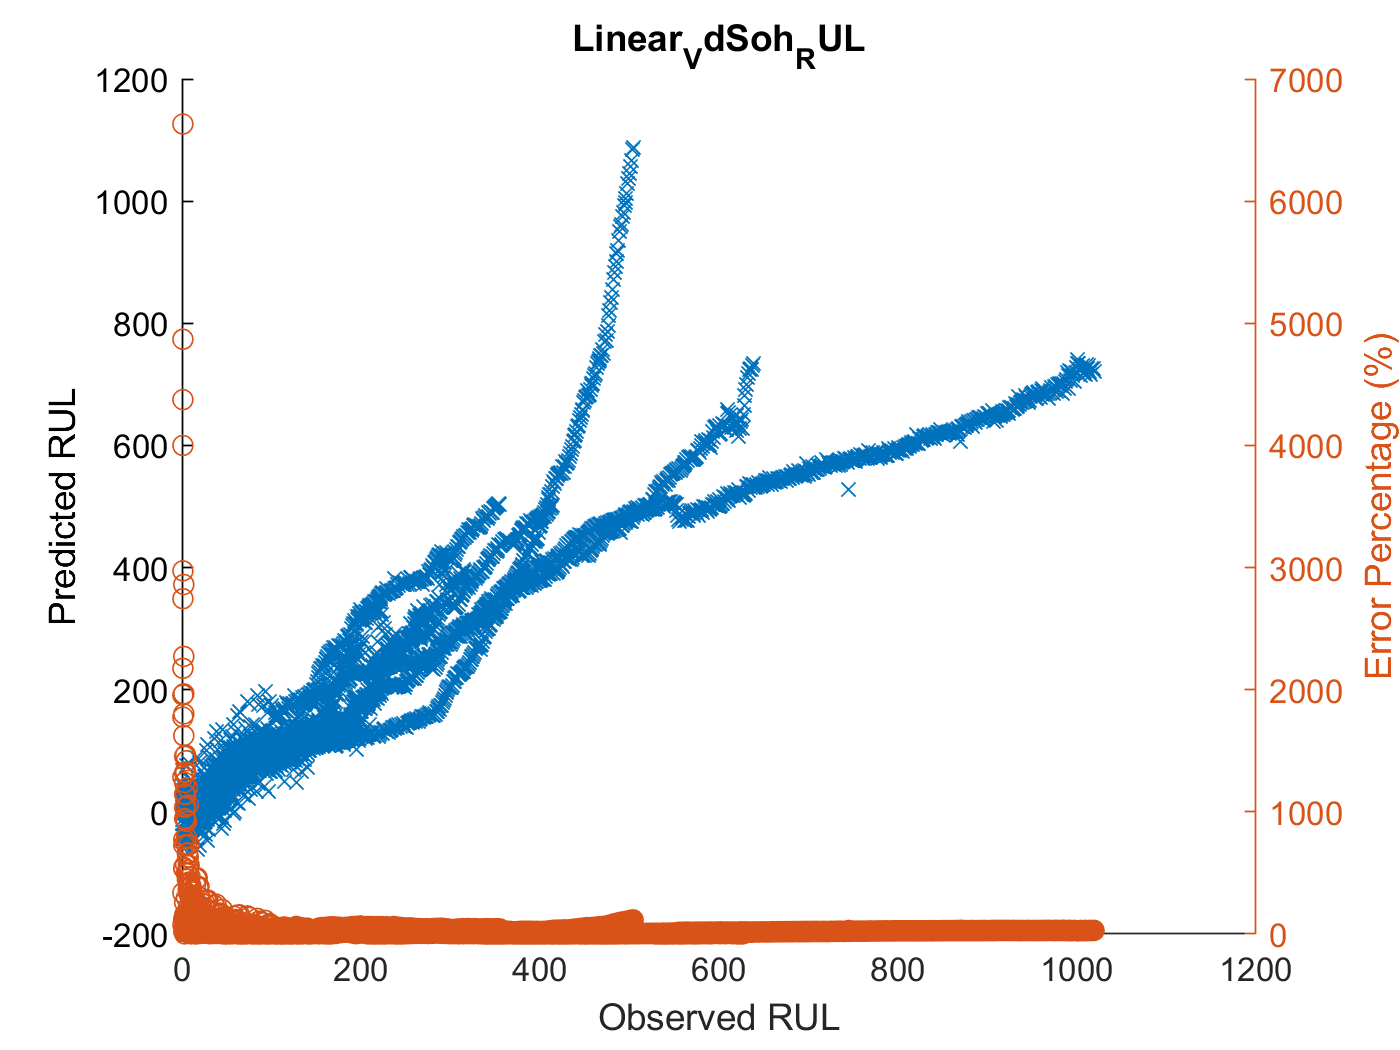


figure
hold on
plot(Y_test_RUL,Yfit_test_VdSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_RUL,Y_test_diff_percentage_VdSohRul,'o');

hold off
title 'Linear_VdSoh_RUL'

# 머신러닝을 위한 기본 설정

epoc_count = 5;
epoc_count_lstm = 3;
%epoc_count = 10; % 시간이 너무 오래 걸린다.
cc_input_size = 20;
fnn_neuron_layer = 20;

# FNN 모델 생성 - 신형회귀와 동일한 20개 뉴런

xnorm_Ic_SOH

xnorm_Ic_SOH =     0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4132    0.1976    0.1976    0.1115    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4874    0.1976    0.1976    0.1110    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4864    0.1976    0.1976    0.1111    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4519    0.1976    0.1976    0.1100    0.0830    0.0830
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5869    0.5870    0.5870    0.5870    0.4465    0.1976    0.1976    0.1099 

xnorm_Vd_SOH 

xnorm_Vd_SOH =     0.9175    0.8739    0.8637    0.8559    0.8482    0.8400    0.8309    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7076    0.6493    0.5376    0.2728    0.0009    0.0009    0.0009
    0.9170    0.8736    0.8634    0.8556    0.8480    0.8397    0.8307    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7074    0.6490    0.5375    0.2720    0.0009    0.0009    0.0009
    0.9177    0.8742    0.8638    0.8560    0.8483    0.8400    0.8310    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7075    0.6489    0.5365    0.2698    0.0009    0.0010    0.0010
    0.9173    0.8737    0.8635    0.8558    0.8481    0.8398    0.8308    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7072    0.6486    0.5365    0.2662    0.0011    0.0013    0.0013
    0.9172    0.8736    0.8635    0.8557    0.8480    0.8398    0.8308    0.8211    0.8106    0.7988    0.7847    0.7669    0.7428    0.7074    0.6488    0.5366    0.2714    0.0009 

xnorm_IcSoh_RUL = [xnorm_Ic_SOH ynorm_SOH ]

xnorm_IcSoh_RUL =     0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4132    0.1976    0.1976    0.1115    0.0830    0.0830    0.9878
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4874    0.1976    0.1976    0.1110    0.0830    0.0830    0.9872
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4864    0.1976    0.1976    0.1111    0.0830    0.0830    0.9867
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.4519    0.1976    0.1976    0.1100    0.0830    0.0830    0.9861
    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5870    0.5869    0.5870    0.5870    0.58

xnorm_VdSoh_RUL = [xnorm_Vd_SOH ynorm_SOH ]

xnorm_VdSoh_RUL =     0.9175    0.8739    0.8637    0.8559    0.8482    0.8400    0.8309    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7076    0.6493    0.5376    0.2728    0.0009    0.0009    0.0009    0.9878
    0.9170    0.8736    0.8634    0.8556    0.8480    0.8397    0.8307    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7074    0.6490    0.5375    0.2720    0.0009    0.0009    0.0009    0.9872
    0.9177    0.8742    0.8638    0.8560    0.8483    0.8400    0.8310    0.8212    0.8107    0.7989    0.7848    0.7670    0.7429    0.7075    0.6489    0.5365    0.2698    0.0009    0.0010    0.0010    0.9867
    0.9173    0.8737    0.8635    0.8558    0.8481    0.8398    0.8308    0.8210    0.8105    0.7987    0.7846    0.7668    0.7427    0.7072    0.6486    0.5365    0.2662    0.0011    0.0013    0.0013    0.9861
    0.9172    0.8736    0.8635    0.8557    0.8480    0.8398    0.8308    0.8211    0.8106    0.7988    0.7847    0.7669    0.7428    0.70


if generate_model
    mdl_Fnn_IcSohRul = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_IcSohRul.divideFcn = 'divideind';
    mdl_Fnn_IcSohRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_IcSohRul.divideParam.valInd = idxValidAll;
    mdl_Fnn_IcSohRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn_IcSohRul.trainParam.showWindow = 0; 
    mdl_Fnn_IcSohRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라

    tic
    [mdl_Fnn_IcSohRul ] = train(mdl_Fnn_IcSohRul, xnorm_IcSoh_RUL', ynorm_RUL', 'useparallel',  'yes');
    toc

    mdl_Fnn_VdSohRul = feedforwardnet(fnn_neuron_layer); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn_VdSohRul.divideFcn = 'divideind';
    mdl_Fnn_VdSohRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn_VdSohRul.divideParam.valInd = idxValidAll;
    mdl_Fnn_VdSohRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn_VdSohRul.trainParam.showWindow = 0; 
    mdl_Fnn_VdSohRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라

    tic
    [mdl_Fnn_VdSohRul ] = train(mdl_Fnn_VdSohRul, xnorm_VdSoh_RUL', ynorm_RUL', 'useparallel',  'yes');
    toc
    
end

# Fnn Ic_SOH

yfit_trainValid_VdSohRul = mdl_Fnn_IcSohRul(xnorm_IcSoh_RUL([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_VdSohRul'

ans =     0.3807    0.5451    0.5449    0.4529    0.4412    0.5295    0.4233    0.5234    0.3764    0.3737    0.4445    0.5185    0.5217    0.3964    0.3764    0.5111    0.5103    0.3505    0.5046    0.5081    0.5165    0.5156    0.3364    0.5122    0.5010    0.4946    0.3406    0.4847    0.3611    0.4832    0.4822    0.4779    0.4743    0.4747    0.4156    0.4761    0.4685    0.4680    0.4666    0.3656    0.4614    0.5435    0.3632    0.4609    0.4699    0.4798    0.4559    0.3128    0.4561    0.3495


yfit_test_IcSohRul = mdl_Fnn_IcSohRul(xnorm_IcSoh_RUL( idxTestAll, :)')';
yfit_test_IcSohRul'

ans =     0.3055    0.3007    0.3012    0.2989    0.2982    0.2952    0.2952    0.2944    0.2921    0.2909    0.2899    0.2865    0.2853    0.2857    0.2866    0.2851    0.2838    0.2839    0.3283    0.3266    0.2812    0.2844    0.2864    0.3337    0.2894    0.2895    0.3337    0.2868    0.2845    0.2804    0.2765    0.2744    0.2743    0.2739    0.2729    0.2724    0.2718    0.2713    0.2697    0.2704    0.2683    0.2703    0.2693    0.2685    0.2685    0.2682    0.2684    0.3086    0.2661    0.2663



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans =     0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444    0.2436    0.2427    0.2419    0.2410    0.2402    0.2393    0.2385    0.2376    0.2368    0.2359    0.2350    0.2342    0.2333    0.2325    0.2316    0.2308    0.2299    0.2291    0.2282    0.2274



Yfit_trainValid_IcSohRul = yfit_trainValid_IcSohRul * yrate_RUL + ymin_RUL;
Yfit_test_IcSohRul = yfit_test_IcSohRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Vd_SOH * yrate_Vd_SOH + ymin_Vd_SOH;


MAE_IcSohRul = mean(abs(Yfit_trainValid_IcSohRul-Y_trainValid_RUL))

MAE_IcSohRul = 81.3417

adjMAE_IcSohRul = MAE_IcSohRul/range(Y_trainValid_RUL)

adjMAE_IcSohRul = 0.0695

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_IcSohRul)'    % Errors

ans =   -35.1277 -121.0257 -122.4742  -71.8861  -66.4404 -110.1138  -56.3803 -107.0186  -28.2966  -25.7643  -64.4452 -103.5751 -106.0070  -38.5652  -27.9992  -99.1317  -99.1926  -12.3723  -95.1402  -98.1341 -104.5073 -105.7463   -5.7745 -101.9405  -93.6671  -89.4454   -3.6826  -83.4251  -13.0824  -83.2828  -82.6266  -79.8166  -77.5770  -78.4834  -48.0894  -77.4863  -75.0585  -75.0175  -74.1195  -15.0825  -71.3893 -101.9819  -13.0793  -72.6402  -69.5738  -79.4552  -70.1946    9.4692  -70.5812  -13.7664


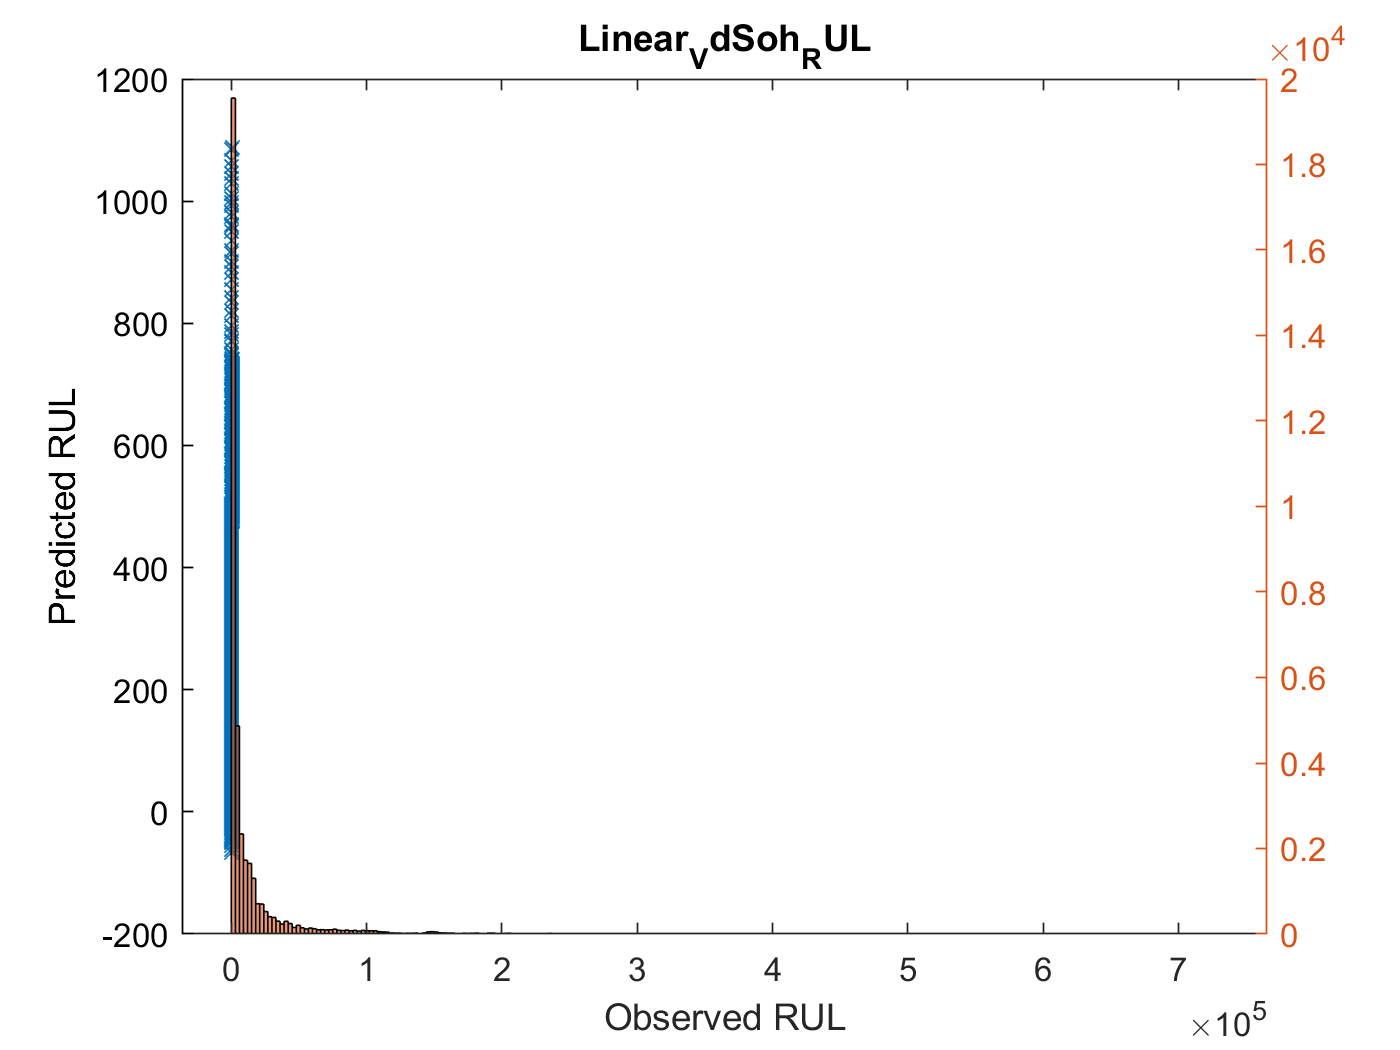

(Y_trainValid_RUL - Yfit_trainValid_IcSohRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_IcSohRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_IcSohRul).^2);   % Mean Squared Error
RMSE_trainValid_IcSohRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_IcSohRul).^2))  % Root Mean Squared Error

RMSE_trainValid_IcSohRul = 117.8511


RMSE_test_IcSohRul = sqrt(mean((Y_test_RUL - Yfit_test_IcSohRul).^2))

RMSE_test_IcSohRul = 94.2713

Y_test_RUL - Yfit_test_IcSohRul

ans =   -42.3821
  -37.7690
  -39.3866
  -37.7039
  -37.8623
  -35.3580
  -36.3379
  -36.4273
  -34.7367
  -34.4012


Y_test_diff_IcSohRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_IcSohRul))

Y_test_diff_IcSohRul = 1.0e+03 *

    0.3160   -0.0424
    0.3150   -0.0378
    0.3140   -0.0394
    0.3130   -0.0377
    0.3120   -0.0379
    0.3110   -0.0354
    0.3100   -0.0363
    0.3090   -0.0364
    0.3080   -0.0347
    0.3070   -0.0344


Y_test_diff_percentage_IcSohRul = abs(Y_test_RUL-Yfit_test_IcSohRul)./Y_test_RUL.*100

Y_test_diff_percentage_IcSohRul = 1.0e+03 *

    0.0134
    0.0120
    0.0125
    0.0120
    0.0121
    0.0114
    0.0117
    0.0118
    0.0113
    0.0112


Y_test_diff_percentage_avg_IcSohRul = sum(Y_test_diff_percentage_IcSohRul)/length(Y_test_diff_percentage_IcSohRul)

Y_test_diff_percentage_avg_IcSohRul = 40.4126

Y_trainValid_diff_IcSohRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcSohRul))

Y_trainValid_diff_IcSohRul = 1.0e+03 *

    0.4280   -0.0351
    0.4270   -0.1210
    0.4260   -0.1225
    0.4250   -0.0719
    0.4240   -0.0664
    0.4230   -0.1101
    0.4220   -0.0564
    0.4210   -0.1070
    0.4200   -0.0283
    0.4190   -0.0258


Y_trainValid_diff_percentage_IcSohRul = abs(Y_trainValid_RUL-Yfit_trainValid_IcSohRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_IcSohRul = 1.0e+04 *

    0.0008
    0.0028
    0.0029
    0.0017
    0.0016
    0.0026
    0.0013
    0.0025
    0.0007
    0.0006


Y_trainValid_diff_percentage_avg_IcSohRul = sum(Y_trainValid_diff_percentage_IcSohRul)/length(Y_trainValid_diff_percentage_IcSohRul)

Y_trainValid_diff_percentage_avg_IcSohRul = 90.7965

num = 1:length(Y_trainValid_RUL);


result = horzcat(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcSohRul),Y_trainValid_diff_percentage_IcSohRul);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 1.0e+04 *

    0.0001    0.0428   -0.0035    0.0008
    0.0002    0.0427   -0.0121    0.0028
    0.0003    0.0426   -0.0122    0.0029
    0.0004    0.0425   -0.0072    0.0017
    0.0005    0.0424   -0.0066    0.0016
    0.0006    0.0423   -0.0110    0.0026
    0.0007    0.0422   -0.0056    0.0013
    0.0008    0.0421   -0.0107    0.0025
    0.0009    0.0420   -0.0028    0.0007
    0.0010    0.0419   -0.0026    0.0006


result_mdl_Fnn_IcSohRul = table(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_IcSohRul),Y_trainValid_diff_percentage_IcSohRul);
result_mdl_Fnn_IcSohRul.Properties.VariableNames = {'bat num','RUL','Error','APE'};
result_mdl_Fnn_IcSohRul

result_mdl_Fnn_IcSohRul = 38367×4 table
    bat num    RUL     Error      APE  
    _______    ___    _______    ______

       1       428    -35.128    8.2074
       2       427    -121.03    28.343
       3       426    -122.47     28.75
       4       425    -71.886    16.914
       5       424     -66.44     15.67
       6       423    -110.11    26.032
       7       422     -56.38     13.36
       8       421    -107.02     25.42
       9       420    -28.297    6.7373
      10       419    -25.764     6.149
      11       418    -64.445    15.418
      12       417    -103.58    24.838
      13       416    -106.01    25.482
      14       415    -38.565    9.2928
      15       414    -27.999    6.7631
      16       413    -99.132    24.003


result_mdl_Fnn_IcSohRul_summary = table(RMSE_test_IcSohRul,Y_trainValid_diff_percentage_avg_IcSohRul);
result_mdl_Fnn_IcSohRul_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_mdl_Fnn_IcSohRul_summary 

result_mdl_Fnn_IcSohRul_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    94.271    90.796



Fnn_IcSohRul_rmse = RMSE_test_IcSohRul

Fnn_IcSohRul_rmse = 94.2713

Fnn_IcSohRul_mape = Y_trainValid_diff_percentage_avg_IcSohRul

Fnn_IcSohRul_mape = 90.7965

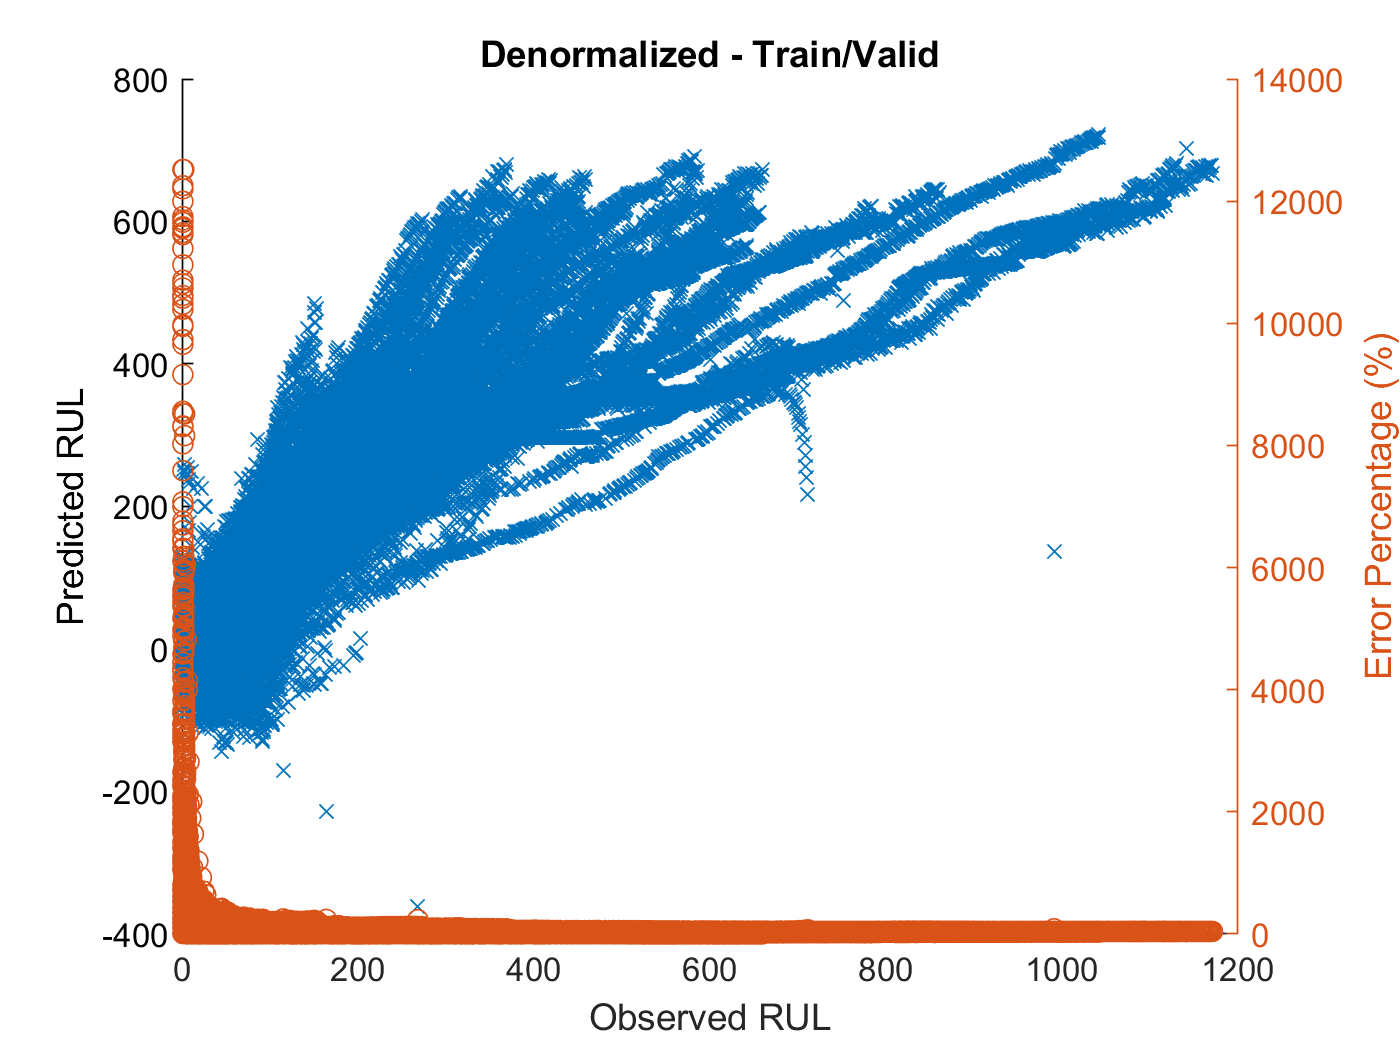


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_IcSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_IcSohRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_IcSohRul

RMSE_test_IcSohRul = 94.2713

Y_trainValid_diff_percentage_avg_IcSohRul

Y_trainValid_diff_percentage_avg_IcSohRul = 90.7965

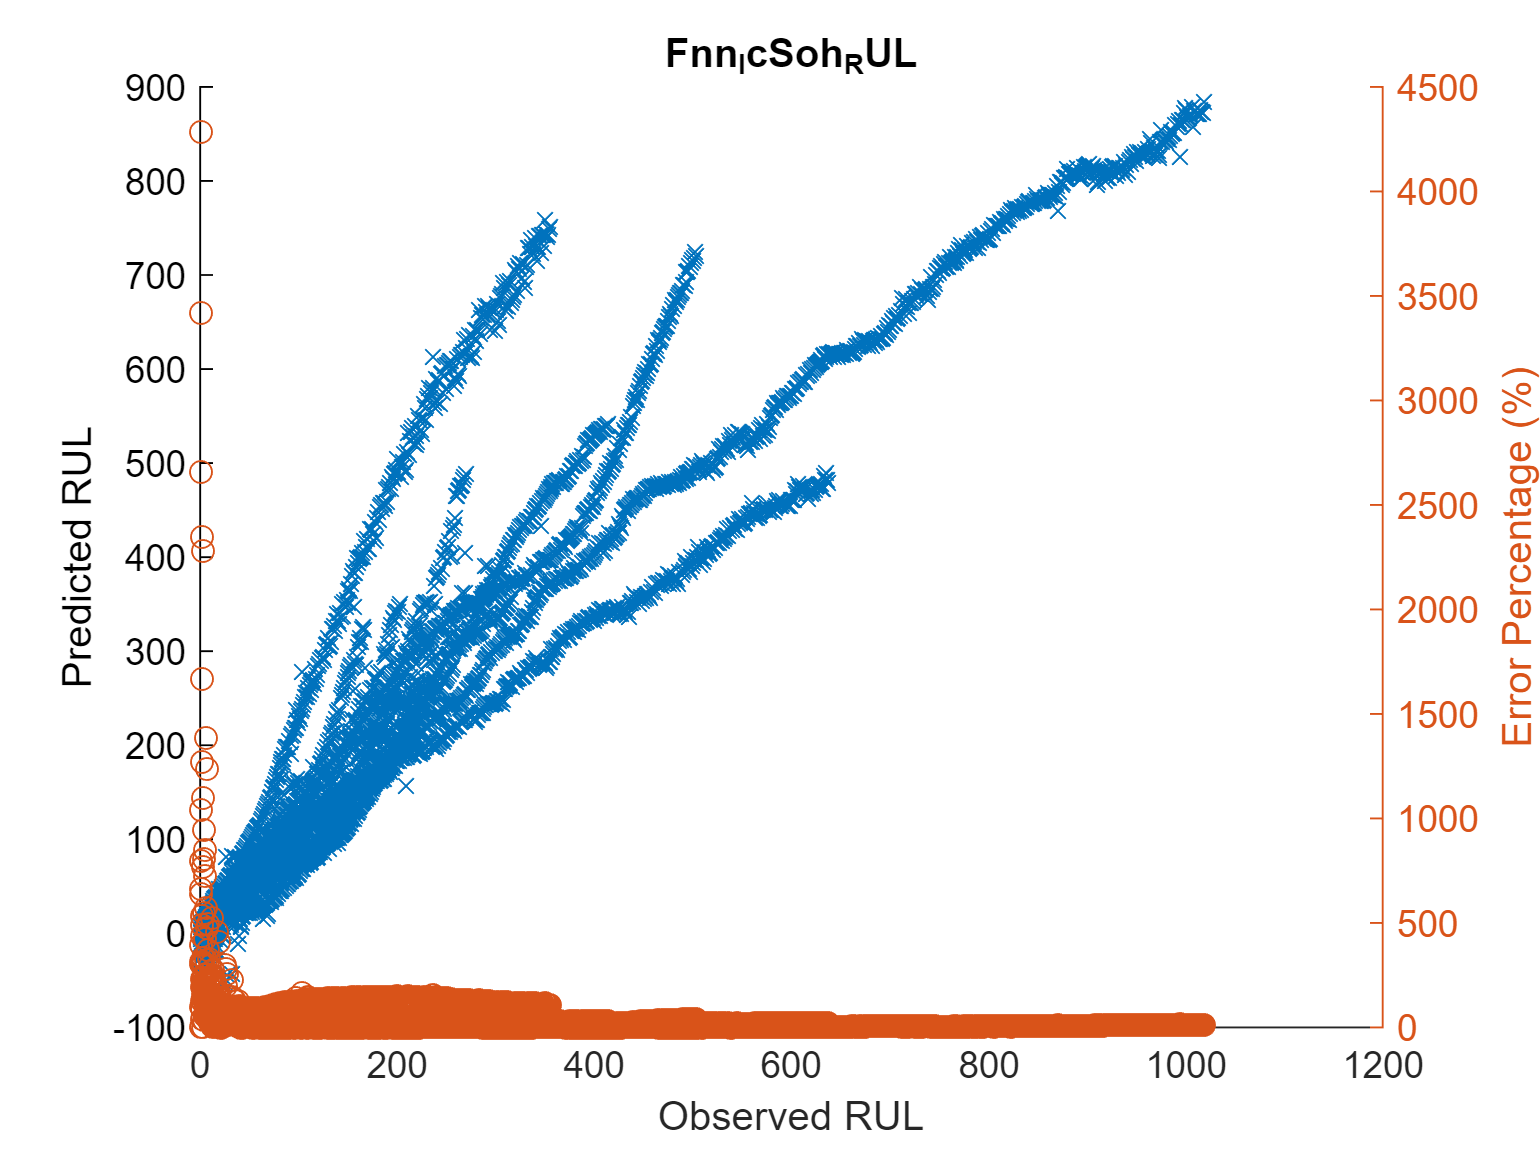


figure
hold on
plot(Y_test_RUL,Yfit_test_IcSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_RUL,Y_test_diff_percentage_IcSohRul,'o');

hold off
title 'Fnn_IcSoh_RUL'

# Fnn Vd_SOH

yfit_trainValid_VdSohRul = mdl_Fnn_VdSohRul(xnorm_VdSoh_RUL([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_VdSohRul'

ans =     0.4063    0.4057    0.4030    0.4012    0.4055    0.4041    0.3998    0.3982    0.3959    0.3955    0.3965    0.4017    0.3984    0.3970    0.3947    0.3950    0.3952    0.3925    0.3937    0.4016    0.4122    0.4104    0.4057    0.4026    0.3980    0.4004    0.3882    0.3845    0.3874    0.3863    0.3849    0.3821    0.3822    0.3847    0.3796    0.3801    0.3779    0.3745    0.3750    0.3727    0.3715    0.3741    0.3738    0.3761    0.3739    0.3689    0.3660    0.3672    0.3734    0.3772


yfit_test_VdSohRul = mdl_Fnn_VdSohRul(xnorm_VdSoh_RUL( idxTestAll, :)')';
yfit_test_VdSohRul'

ans =     0.3726    0.3665    0.3644    0.3609    0.3593    0.3574    0.3569    0.3554    0.3525    0.3506    0.3503    0.3481    0.3462    0.3558    0.3571    0.3445    0.3404    0.3394    0.3374    0.3320    0.3427    0.3650    0.3823    0.3929    0.3978    0.4007    0.4005    0.3983    0.3751    0.3385    0.3161    0.3223    0.3205    0.3180    0.3154    0.3130    0.3138    0.3094    0.3082    0.3055    0.3039    0.3028    0.3058    0.3041    0.2988    0.2990    0.2996    0.2958    0.2950    0.3039



y_trainValid_RUL'

ans =     0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402    0.3393    0.3385    0.3376    0.3368    0.3359    0.3350    0.3342    0.3333    0.3325    0.3316    0.3308    0.3299    0.3291    0.3282    0.3274    0.3265    0.3256    0.3248    0.3239    0.3231


y_test_RUL'

ans = 1×4488
    0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444



Yfit_trainValid_VdSohRul = yfit_trainValid_VdSohRul * yrate_RUL + ymin_RUL;
Yfit_test_VdSohRul = yfit_test_VdSohRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Vd_SOH * yrate_Vd_SOH + ymin_Vd_SOH;


MAE_VdSohRul = mean(abs(Yfit_trainValid_VdSohRul-Y_trainValid_RUL))

MAE_VdSohRul = 63.8584

adjMAE_VdSohRul = MAE_VdSohRul/range(Y_trainValid_RUL)

adjMAE_VdSohRul = 0.0546

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_VdSohRul)'    % Errors

ans = 1×38367
  -48.4092  -48.6737  -46.4680  -45.4482  -51.4101  -50.7843  -46.7710  -45.9147  -44.1693  -44.7169  -46.9239  -53.9952  -51.1291  -50.4381  -48.7565  -50.1940  -51.4388  -49.2451  -51.6758  -61.8507  -75.2939  -74.1794  -69.6835  -67.0809  -62.6643  -66.4389  -53.2518  -49.8426  -54.2289  -53.9721


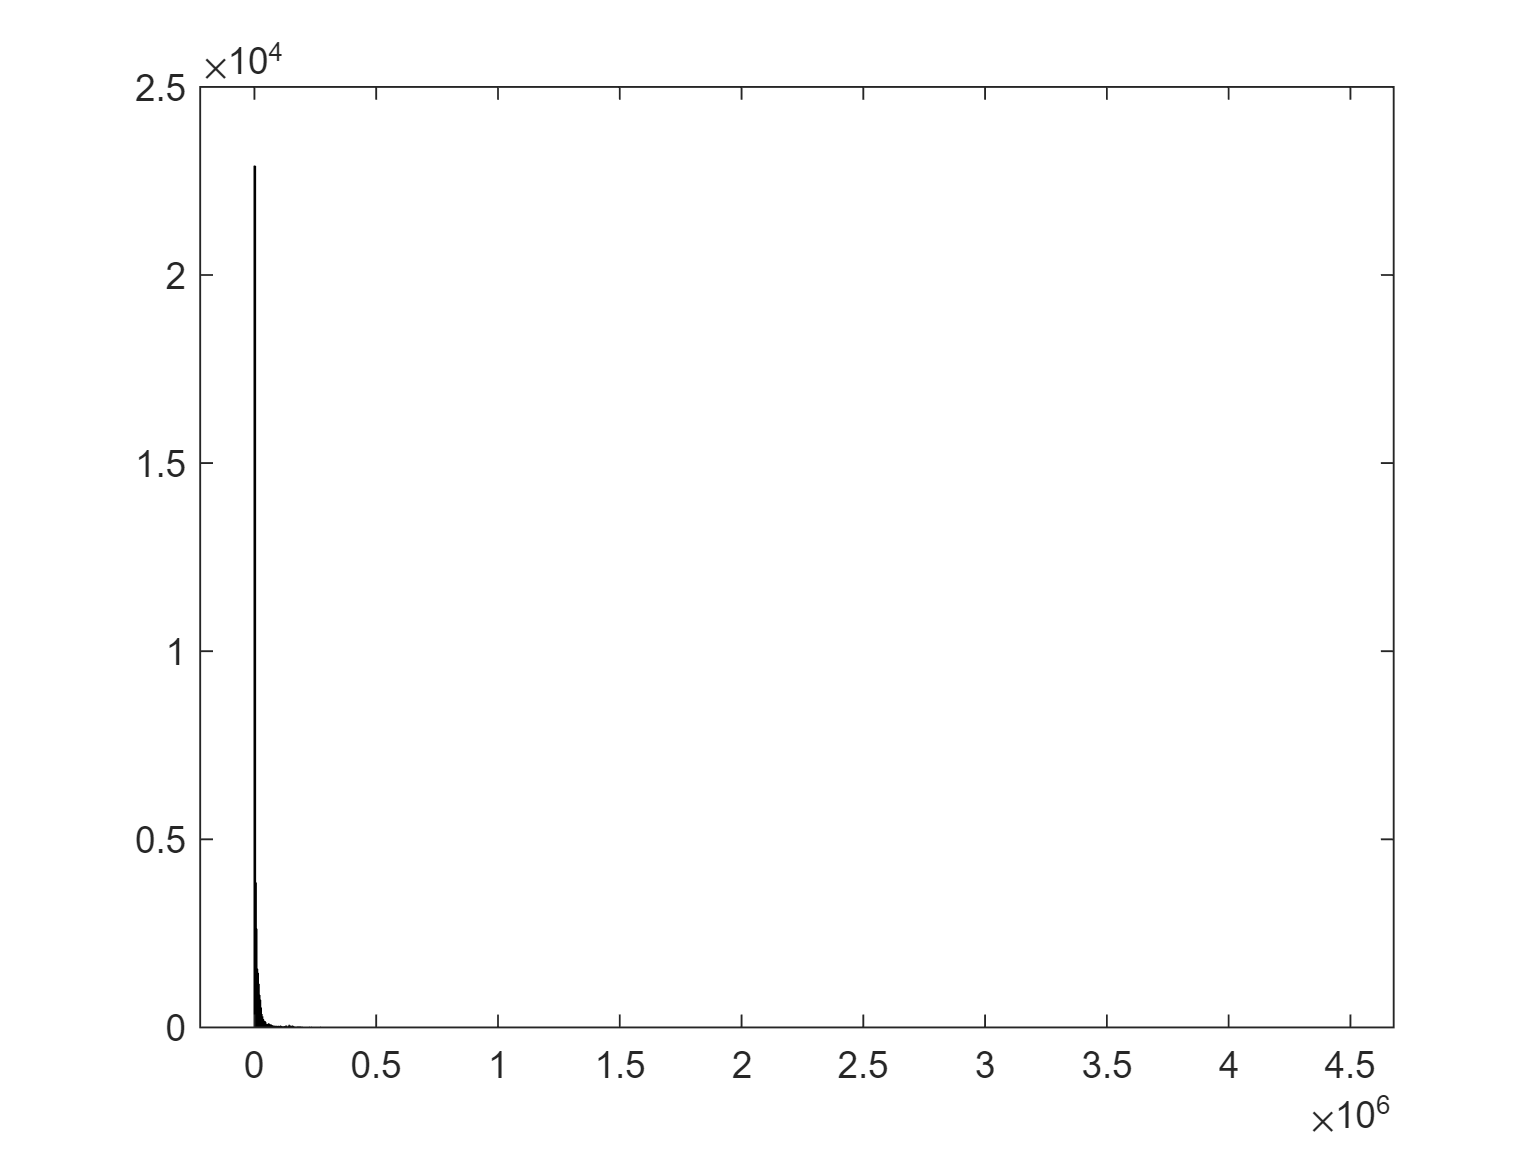

(Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2;   % Squared Error

figure
histogram((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2)

%xlim([-2,100])

mean((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2);   % Mean Squared Error
RMSE_trainValid_VdSohRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2))  % Root Mean Squared Error

RMSE_trainValid_VdSohRul = 92.7805


RMSE_test_VdSohRul = sqrt(mean((Y_test_RUL - Yfit_test_VdSohRul).^2))

RMSE_test_VdSohRul = 95.3540

Y_test_RUL - Yfit_test_VdSohRul

ans = 4488×1
 -120.8947
 -114.7674
 -113.3659
 -110.2906
 -109.4007
 -108.1174
 -108.6314
 -107.8187
 -105.4572
 -104.1784


Y_test_diff_VdSohRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_VdSohRul))

Y_test_diff_VdSohRul = 4488×2
  316.0000 -120.8947
  315.0000 -114.7674
  314.0000 -113.3659
  313.0000 -110.2906
  312.0000 -109.4007
  311.0000 -108.1174
  310.0000 -108.6314
  309.0000 -107.8187
  308.0000 -105.4572
  307.0000 -104.1784


Y_test_diff_percentage_VdSohRul = abs(Y_test_RUL-Yfit_test_VdSohRul)./Y_test_RUL.*100

Y_test_diff_percentage_VdSohRul = 4488×1
   38.2578
   36.4341
   36.1038
   35.2366
   35.0643
   34.7644
   35.0424
   34.8928
   34.2393
   33.9343


Y_test_diff_percentage_avg_VdSohRul = sum(Y_test_diff_percentage_VdSohRul)/length(Y_test_diff_percentage_VdSohRul)

Y_test_diff_percentage_avg_VdSohRul = 61.2152

Y_trainValid_diff_VdSohRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul))

Y_trainValid_diff_VdSohRul = 38367×2
  428.0000  -48.4092
  427.0000  -48.6737
  426.0000  -46.4680
  425.0000  -45.4482
  424.0000  -51.4101
  423.0000  -50.7843
  422.0000  -46.7710
  421.0000  -45.9147
  420.0000  -44.1693
  419.0000  -44.7169


Y_trainValid_diff_percentage_VdSohRul = abs(Y_trainValid_RUL-Yfit_trainValid_VdSohRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_VdSohRul = 38367×1
   11.3106
   11.3990
   10.9080
   10.6937
   12.1250
   12.0057
   11.0832
   10.9061
   10.5165
   10.6723


Y_trainValid_diff_percentage_avg_VdSohRul = sum(Y_trainValid_diff_percentage_VdSohRul)/length(Y_trainValid_diff_percentage_VdSohRul)

Y_trainValid_diff_percentage_avg_VdSohRul = 69.1611

num = 1:length(Y_trainValid_RUL);


result = horzcat(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul),Y_trainValid_diff_percentage_VdSohRul);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 38367×4
    1.0000  428.0000  -48.4092   11.3106
    2.0000  427.0000  -48.6737   11.3990
    3.0000  426.0000  -46.4680   10.9080
    4.0000  425.0000  -45.4482   10.6937
    5.0000  424.0000  -51.4101   12.1250
    6.0000  423.0000  -50.7843   12.0057
    7.0000  422.0000  -46.7710   11.0832
    8.0000  421.0000  -45.9147   10.9061
    9.0000  420.0000  -44.1693   10.5165
   10.0000  419.0000  -44.7169   10.6723


result_mdl_Fnn_VdSohRul = table(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul),Y_trainValid_diff_percentage_VdSohRul);
result_mdl_Fnn_VdSohRul.Properties.VariableNames = {'bat num','RUL','Error','APE'};
result_mdl_Fnn_VdSohRul

result_mdl_Fnn_VdSohRul = 38367×4 table
    bat num    RUL     Error      APE  
    _______    ___    _______    ______

       1       428    -48.409    11.311
       2       427    -48.674    11.399
       3       426    -46.468    10.908
       4       425    -45.448    10.694
       5       424     -51.41    12.125
       6       423    -50.784    12.006
       7       422    -46.771    11.083
       8       421    -45.915    10.906
       9       420    -44.169    10.517
      10       419    -44.717    10.672
      11       418    -46.924    11.226
      12       417    -53.995    12.948
      13       416    -51.129    12.291
      14       415    -50.438    12.154
      15       414    -48.757    11.777
      16       413    -50.194    12.154


result_mdl_Fnn_VdSohRul_summary = table(RMSE_test_VdSohRul,Y_trainValid_diff_percentage_avg_VdSohRul);
result_mdl_Fnn_VdSohRul_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_mdl_Fnn_VdSohRul_summary 

result_mdl_Fnn_VdSohRul_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    95.354    69.161



Fnn_VdSohRul_rmse = RMSE_test_VdSohRul

Fnn_VdSohRul_rmse = 95.3540

Fnn_VdSohRul_mape = Y_trainValid_diff_percentage_avg_VdSohRul

Fnn_VdSohRul_mape = 69.1611

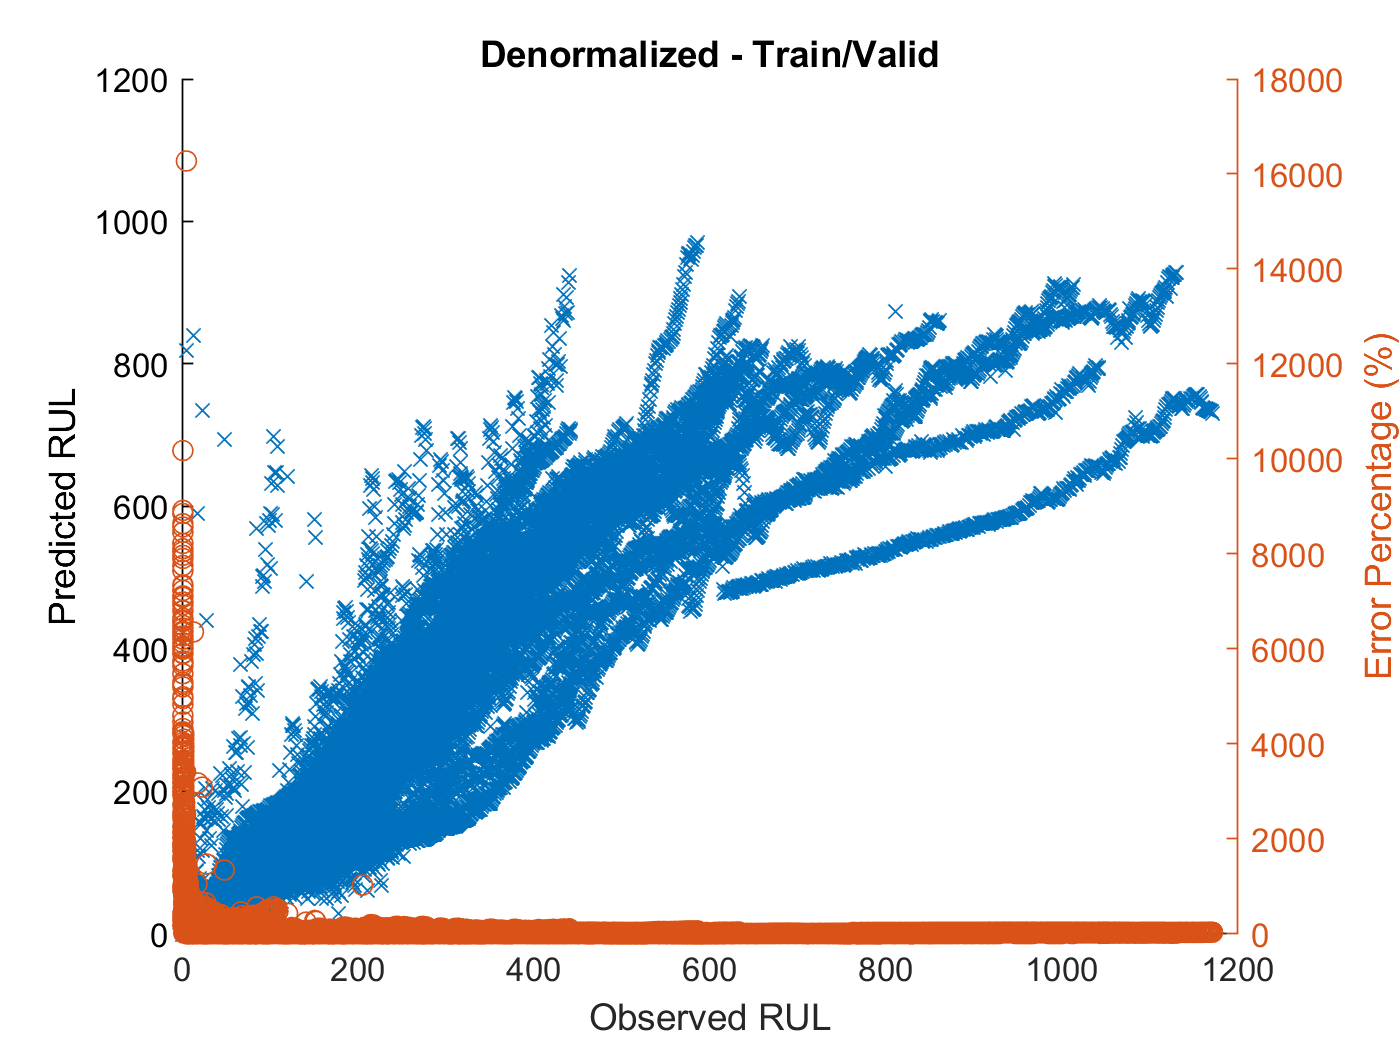


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_VdSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), 
ylim([0 1200])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_VdSohRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_VdSohRul

RMSE_test_VdSohRul = 95.3540

Y_trainValid_diff_percentage_avg_VdSohRul

Y_trainValid_diff_percentage_avg_VdSohRul = 69.1611

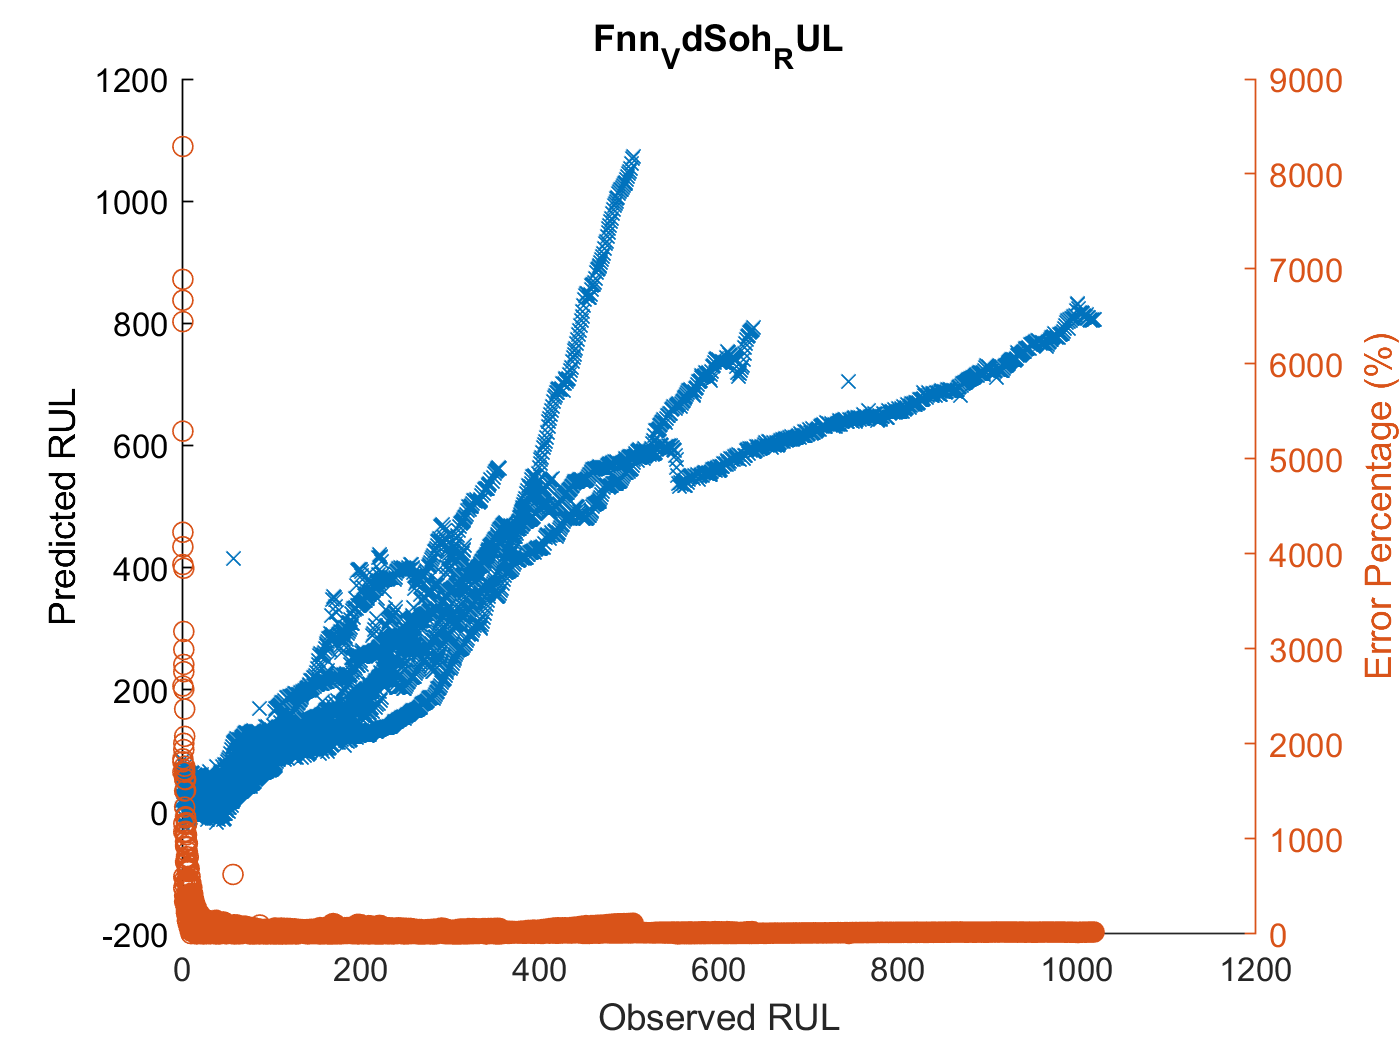


figure
hold on
plot(Y_test_RUL,Yfit_test_VdSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_RUL,Y_test_diff_percentage_VdSohRul,'o');

hold off
title 'Fnn_VdSoh_RUL'

# FNN 모델 생성 - 3개 layer로 더 deep하게 -  40 20 10개 뉴런

fnn_neuron_layer3 = [40,20,10];

if generate_model
    mdl_Fnn3_IcSohRul = feedforwardnet(fnn_neuron_layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_IcSohRul.divideFcn = 'divideind';
    mdl_Fnn3_IcSohRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_IcSohRul.divideParam.valInd = idxValidAll;
    mdl_Fnn3_IcSohRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn3_IcSohRul.trainParam.showWindow = 0; 
    mdl_Fnn3_IcSohRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_IcSohRul ] = train(mdl_Fnn3_IcSohRul, xnorm_IcSoh_RUL', ynorm_RUL', 'useparallel',  'yes');
    toc

    mdl_Fnn3_VdSohRul = feedforwardnet(fnn_neuron_layer3); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
    mdl_Fnn3_VdSohRul.divideFcn = 'divideind';
    mdl_Fnn3_VdSohRul.divideParam.trainInd = idxTrainAll;
    mdl_Fnn3_VdSohRul.divideParam.valInd = idxValidAll;
    mdl_Fnn3_VdSohRul.divideParam.testInd = idxTestAll; 
        
    %netFNN1__1.divideParam
    % https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
    mdl_Fnn3_VdSohRul.trainParam.showWindow = 0; 
    mdl_Fnn3_VdSohRul.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
    tic
    [mdl_Fnn3_VdSohRul ] = train(mdl_Fnn3_VdSohRul, xnorm_VdSoh_RUL', ynorm_RUL', 'useparallel',  'yes');
    toc
    
end


# Fnn3 Ic_SOH

yfit_trainValid_VdSohRul = mdl_Fnn3_IcSohRul(xnorm_IcSoh_RUL([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_VdSohRul'

ans = 1×38367
    0.4384    0.5914    0.5907    0.5058    0.4946    0.5772    0.4780    0.5712    0.4351    0.4326    0.4980    0.5664    0.5689    0.4532    0.4345    0.5591    0.5582    0.4108    0.5528    0.5557    0.5628    0.5614    0.3971    0.5584    0.5487    0.5428    0.3960    0.5335    0.4003    0.5318


yfit_test_VdSohRul = mdl_Fnn3_IcSohRul(xnorm_IcSoh_RUL( idxTestAll, :)')';
yfit_test_VdSohRul'

ans = 1×4488
    0.2933    0.2911    0.2908    0.2896    0.2890    0.2875    0.2871    0.2866    0.2853    0.2845    0.2837    0.2821    0.2813    0.2810    0.2810    0.2801    0.2792    0.2789    0.3074    0.3063    0.2768    0.2775    0.2781    0.3073    0.2784    0.2781    0.3061    0.2762    0.2750    0.2730



y_trainValid_RUL'

ans = 1×38367
    0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402


y_test_RUL'

ans = 1×4488
    0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444



Yfit_trainValid_VdSohRul = yfit_trainValid_VdSohRul * yrate_RUL + ymin_RUL;
Yfit_test_VdSohRul = yfit_test_VdSohRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Vd_SOH * yrate_Vd_SOH + ymin_Vd_SOH;


MAE_VdSohRul = mean(abs(Yfit_trainValid_VdSohRul-Y_trainValid_RUL))

MAE_VdSohRul = 71.7965

adjMAE_VdSohRul = MAE_VdSohRul/range(Y_trainValid_RUL)

adjMAE_VdSohRul = 0.0614

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_VdSohRul)'    % Errors

ans = 1×38367
  -85.9339 -265.9751 -266.1651 -167.8441 -155.7037 -253.2932 -138.2263 -248.2488  -90.0597  -88.1575 -165.6818 -246.7350 -250.6460 -116.1911  -95.4071 -242.1062 -242.0822  -70.5959 -237.7989 -242.1532 -251.4388 -250.8506  -59.6105 -249.3541 -238.9496 -233.1120  -62.3458 -224.2268  -69.3297 -224.1859


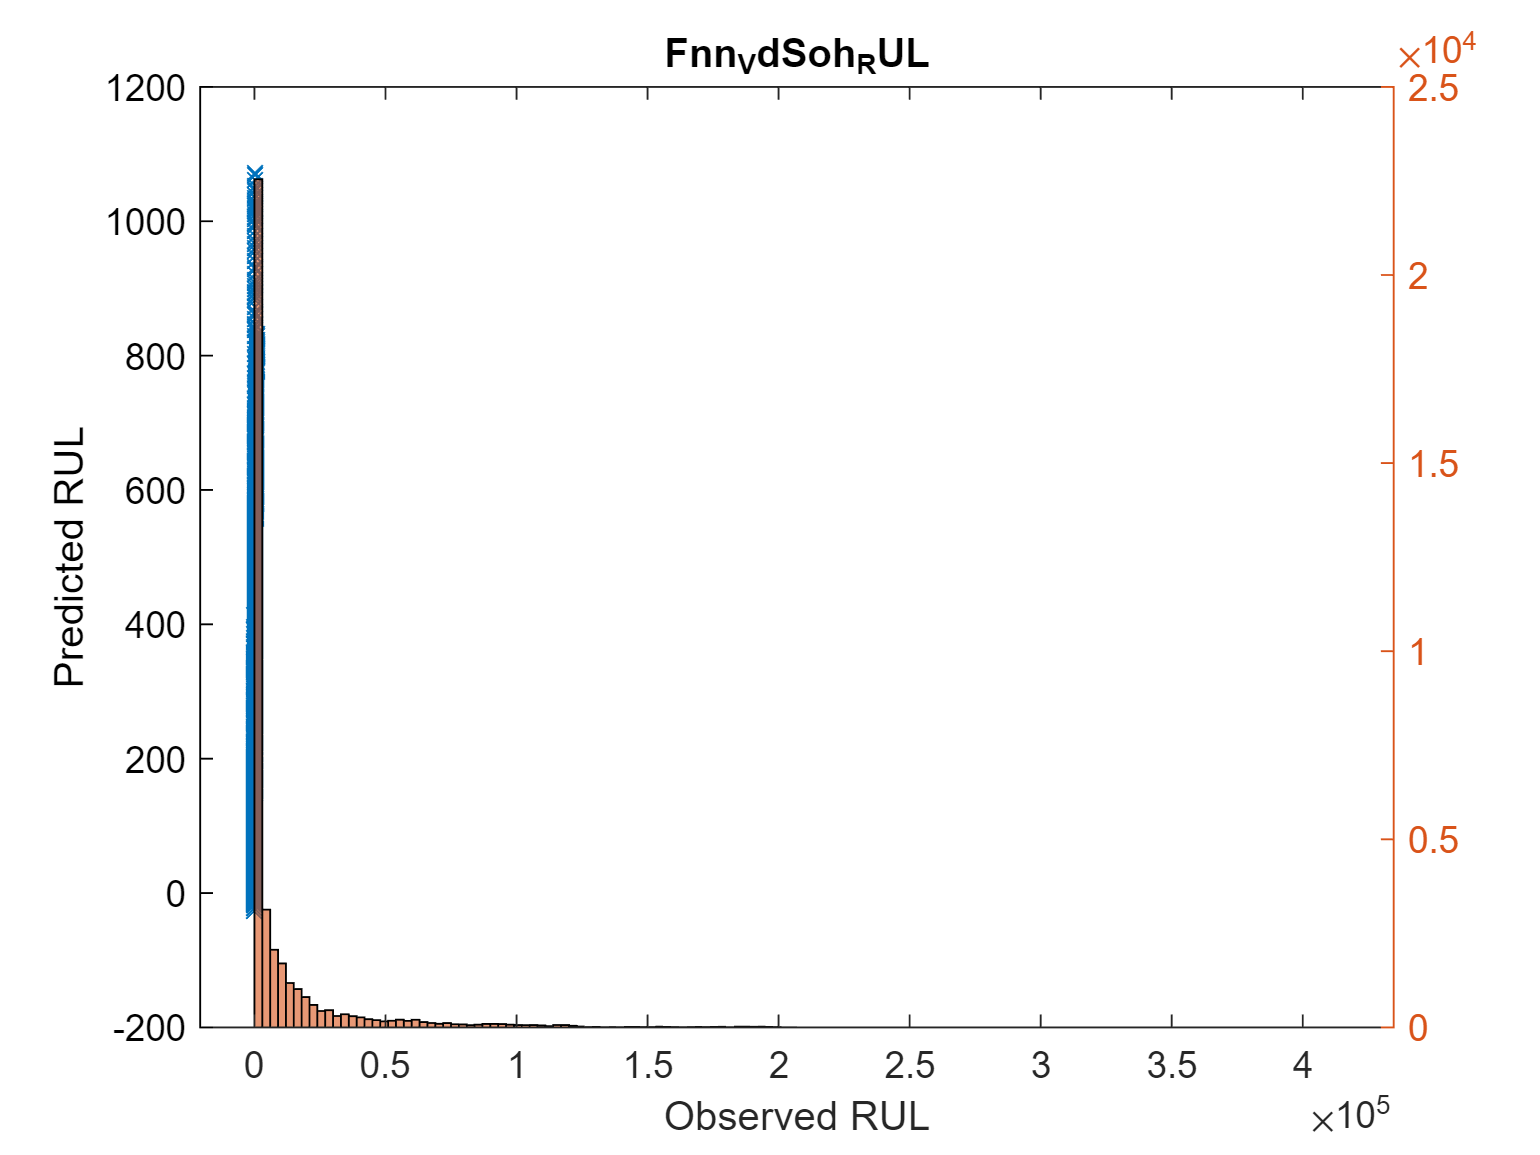

(Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2);   % Mean Squared Error
RMSE_trainValid_VdSohRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2))  % Root Mean Squared Error

RMSE_trainValid_VdSohRul = 108.4973


RMSE_test_VdSohRul = sqrt(mean((Y_test_RUL - Yfit_test_VdSohRul).^2))

RMSE_test_VdSohRul = 97.6313

Y_test_RUL - Yfit_test_VdSohRul

ans = 4488×1
  -28.1217
  -26.5300
  -27.2676
  -26.8431
  -27.1619
  -26.4095
  -26.9624
  -27.2961
  -26.8450
  -26.8461


Y_test_diff_VdSohRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_VdSohRul))

Y_test_diff_VdSohRul = 4488×2
  316.0000  -28.1217
  315.0000  -26.5300
  314.0000  -27.2676
  313.0000  -26.8431
  312.0000  -27.1619
  311.0000  -26.4095
  310.0000  -26.9624
  309.0000  -27.2961
  308.0000  -26.8450
  307.0000  -26.8461


Y_test_diff_percentage_VdSohRul = abs(Y_test_RUL-Yfit_test_VdSohRul)./Y_test_RUL.*100

Y_test_diff_percentage_VdSohRul = 4488×1
    8.8993
    8.4222
    8.6840
    8.5761
    8.7057
    8.4918
    8.6975
    8.8337
    8.7159
    8.7447


Y_test_diff_percentage_avg_VdSohRul = sum(Y_test_diff_percentage_VdSohRul)/length(Y_test_diff_percentage_VdSohRul)

Y_test_diff_percentage_avg_VdSohRul = 48.0028

Y_trainValid_diff_VdSohRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul))

Y_trainValid_diff_VdSohRul = 38367×2
  428.0000  -85.9339
  427.0000 -265.9751
  426.0000 -266.1651
  425.0000 -167.8441
  424.0000 -155.7037
  423.0000 -253.2932
  422.0000 -138.2263
  421.0000 -248.2488
  420.0000  -90.0597
  419.0000  -88.1575


Y_trainValid_diff_percentage_VdSohRul = abs(Y_trainValid_RUL-Yfit_trainValid_VdSohRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_VdSohRul = 38367×1
   20.0780
   62.2892
   62.4801
   39.4927
   36.7226
   59.8802
   32.7550
   58.9665
   21.4428
   21.0400


Y_trainValid_diff_percentage_avg_VdSohRul = sum(Y_trainValid_diff_percentage_VdSohRul)/length(Y_trainValid_diff_percentage_VdSohRul)

Y_trainValid_diff_percentage_avg_VdSohRul = 44.1529

num = 1:length(Y_trainValid_RUL);


result = horzcat(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul),Y_trainValid_diff_percentage_VdSohRul);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 38367×4
    1.0000  428.0000  -85.9339   20.0780
    2.0000  427.0000 -265.9751   62.2892
    3.0000  426.0000 -266.1651   62.4801
    4.0000  425.0000 -167.8441   39.4927
    5.0000  424.0000 -155.7037   36.7226
    6.0000  423.0000 -253.2932   59.8802
    7.0000  422.0000 -138.2263   32.7550
    8.0000  421.0000 -248.2488   58.9665
    9.0000  420.0000  -90.0597   21.4428
   10.0000  419.0000  -88.1575   21.0400


result_mdl_Fnn3_IcSohRul = table(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul),Y_trainValid_diff_percentage_VdSohRul);
result_mdl_Fnn3_IcSohRul.Properties.VariableNames = {'bat num','RUL','Error','APE'};
result_mdl_Fnn3_IcSohRul

result_mdl_Fnn3_IcSohRul = 38367×4 table
    bat num    RUL     Error      APE  
    _______    ___    _______    ______

       1       428    -85.934    20.078
       2       427    -265.98    62.289
       3       426    -266.17     62.48
       4       425    -167.84    39.493
       5       424     -155.7    36.723
       6       423    -253.29     59.88
       7       422    -138.23    32.755
       8       421    -248.25    58.966
       9       420     -90.06    21.443
      10       419    -88.157     21.04
      11       418    -165.68    39.637
      12       417    -246.74    59.169
      13       416    -250.65    60.251
      14       415    -116.19    27.998
      15       414    -95.407    23.045
      16       413    -242.11    58.621


result_mdl_Fnn3_IcSohRul_summary = table(RMSE_test_VdSohRul,Y_trainValid_diff_percentage_avg_VdSohRul);
result_mdl_Fnn3_IcSohRul_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_mdl_Fnn3_IcSohRul_summary 

result_mdl_Fnn3_IcSohRul_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    97.631    44.153



Fnn3_IcSohRul_rmse = RMSE_test_IcSohRul

Fnn3_IcSohRul_rmse = 94.2713

Fnn3_IcSohRul_mape = Y_trainValid_diff_percentage_avg_IcSohRul

Fnn3_IcSohRul_mape = 90.7965

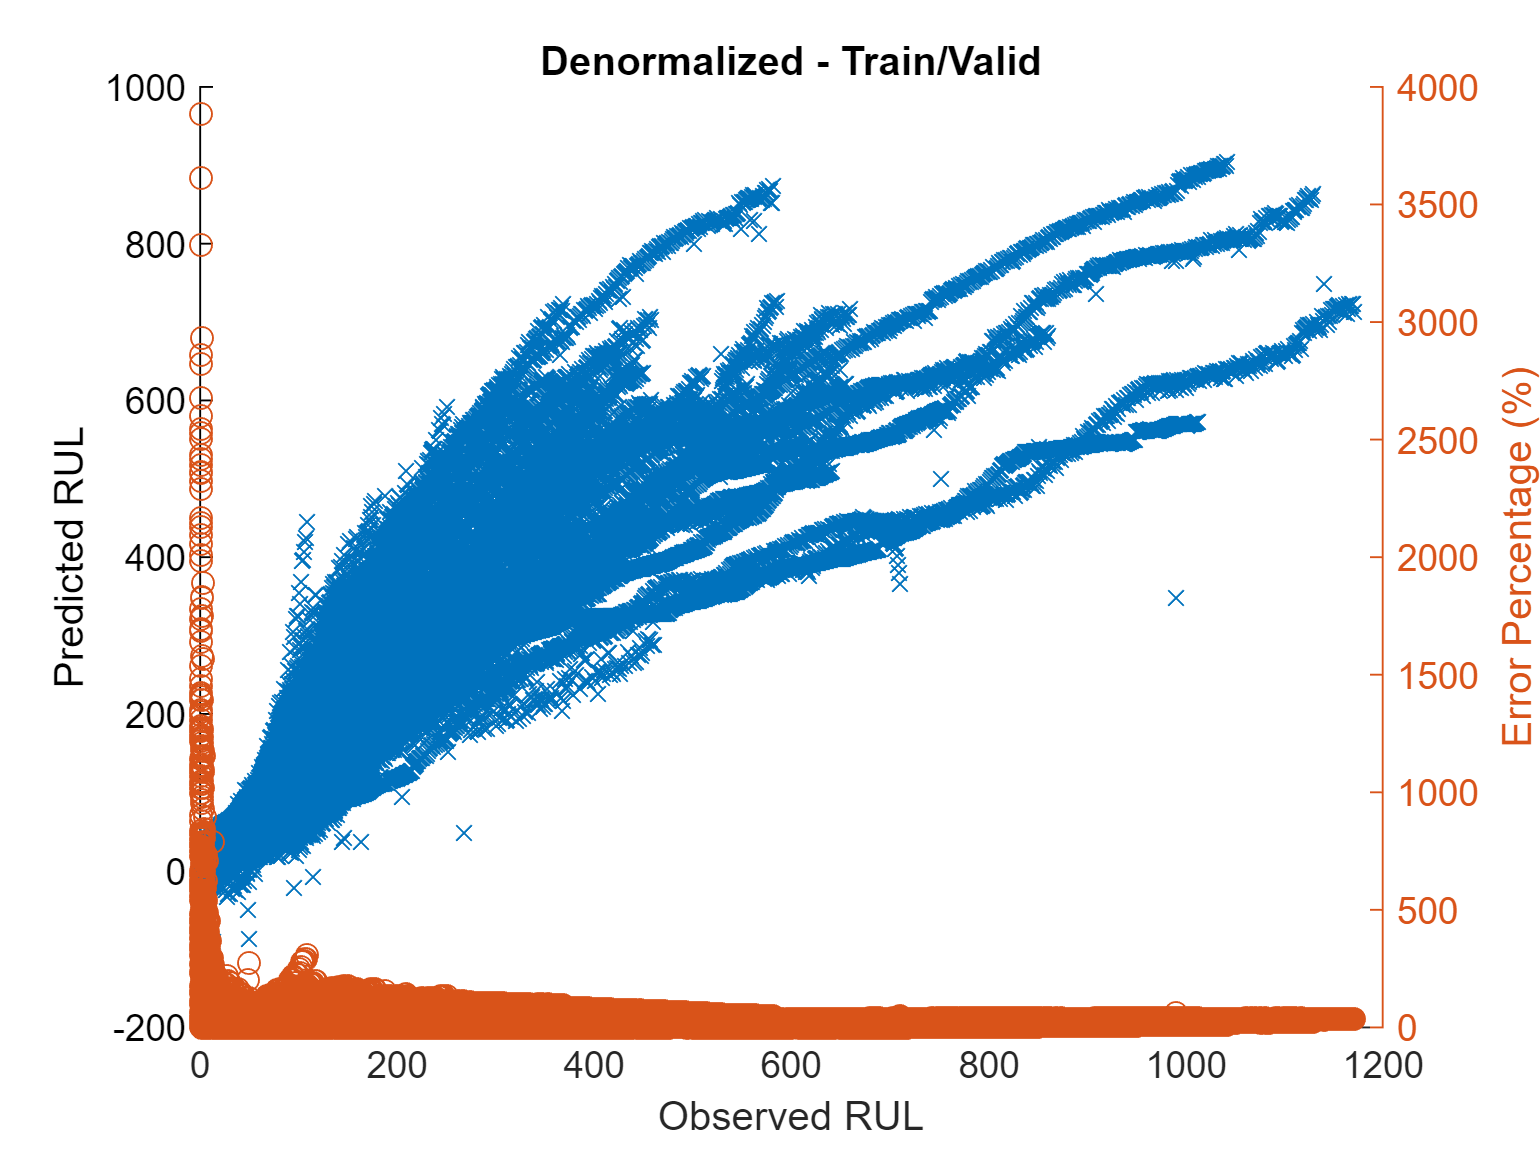


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_VdSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_VdSohRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_VdSohRul

RMSE_test_VdSohRul = 97.6313

Y_trainValid_diff_percentage_avg_VdSohRul

Y_trainValid_diff_percentage_avg_VdSohRul = 44.1529

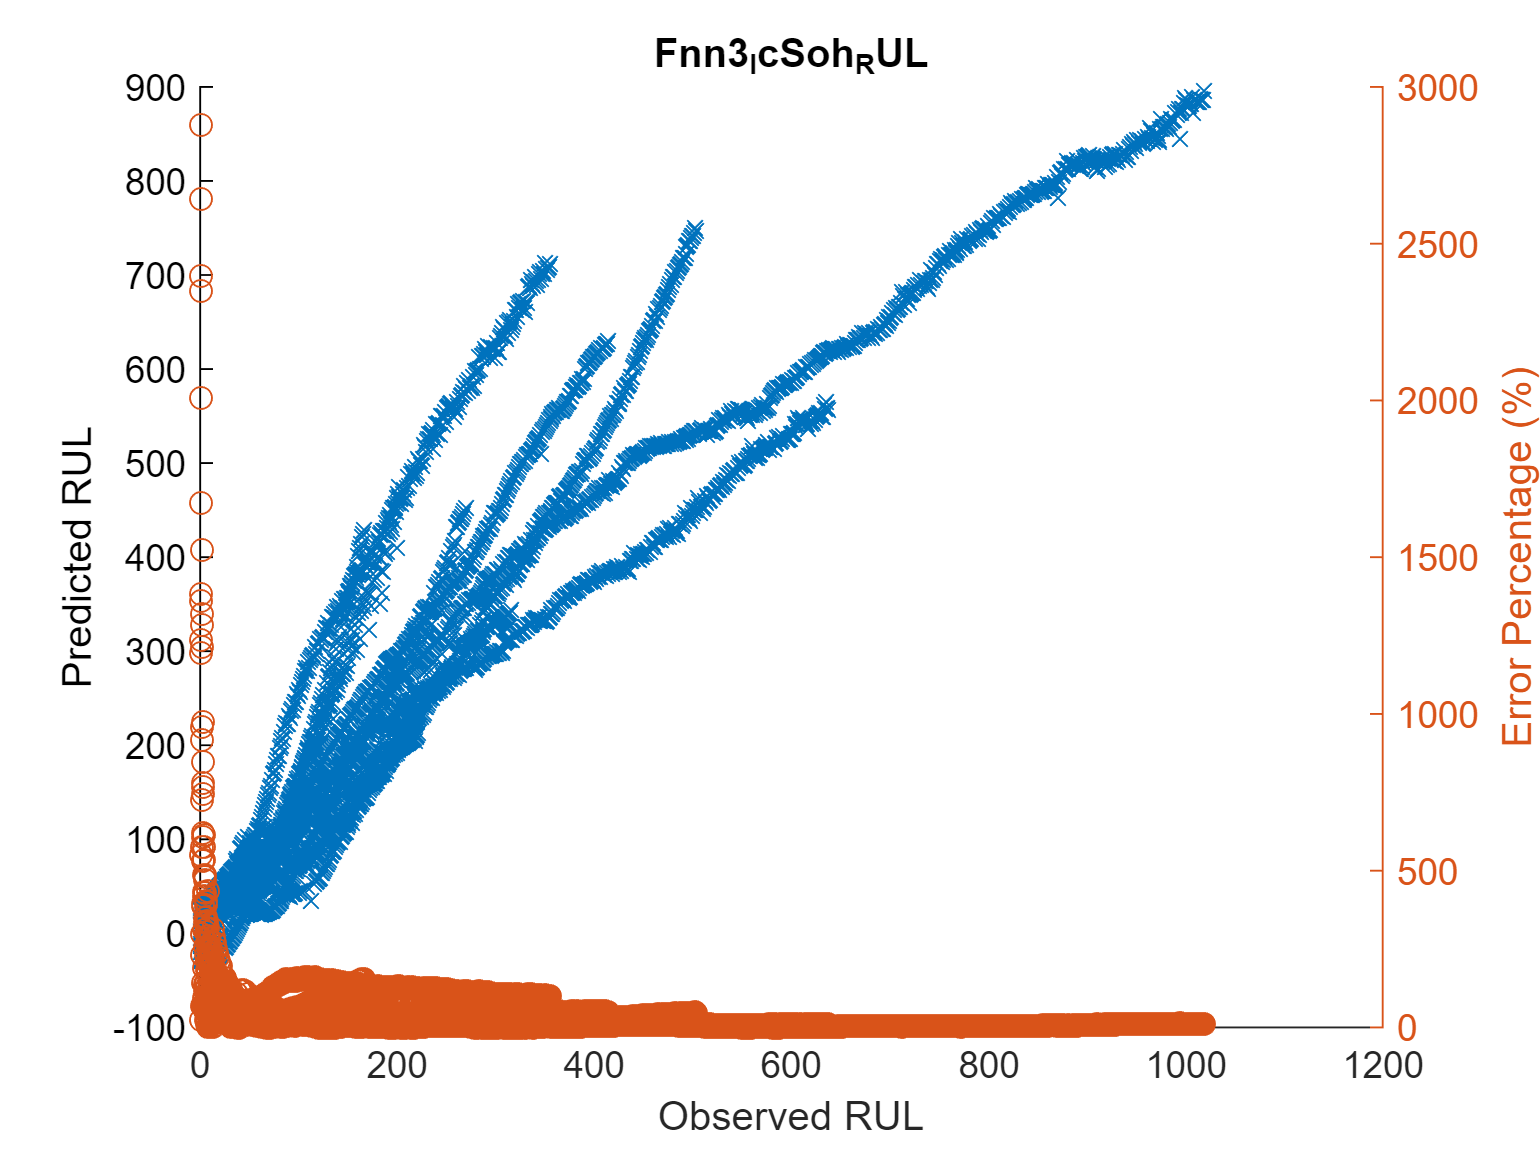


figure
hold on
plot(Y_test_RUL,Yfit_test_VdSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_RUL,Y_test_diff_percentage_VdSohRul,'o');

hold off
title 'Fnn3_IcSoh_RUL'

# Fnn3 Vd_SOH

yfit_trainValid_VdSohRul = mdl_Fnn3_VdSohRul(xnorm_VdSoh_RUL([idxTrainAll idxValidAll ], :)')';
yfit_trainValid_VdSohRul'

ans = 1×38367
    0.3407    0.3411    0.3378    0.3376    0.3401    0.3387    0.3347    0.3347    0.3329    0.3319    0.3327    0.3362    0.3354    0.3320    0.3309    0.3319    0.3310    0.3274    0.3302    0.3375    0.3443    0.3436    0.3411    0.3382    0.3331    0.3276    0.3248    0.3226    0.3240    0.3230


yfit_test_VdSohRul = mdl_Fnn3_VdSohRul(xnorm_VdSoh_RUL( idxTestAll, :)')';
yfit_test_VdSohRul'

ans = 1×4488
    0.3233    0.3189    0.3168    0.3146    0.3133    0.3120    0.3108    0.3105    0.3085    0.3074    0.3069    0.3050    0.3041    0.3111    0.3120    0.3032    0.3000    0.2992    0.2987    0.2940    0.3020    0.3178    0.3312    0.3395    0.3445    0.3465    0.3464    0.3449    0.3253    0.2991



y_trainValid_RUL'

ans = 1×38367
    0.3650    0.3641    0.3632    0.3624    0.3615    0.3607    0.3598    0.3590    0.3581    0.3573    0.3564    0.3556    0.3547    0.3538    0.3530    0.3521    0.3513    0.3504    0.3496    0.3487    0.3479    0.3470    0.3462    0.3453    0.3444    0.3436    0.3427    0.3419    0.3410    0.3402


y_test_RUL'

ans = 1×4488
    0.2692    0.2684    0.2675    0.2667    0.2658    0.2650    0.2641    0.2632    0.2624    0.2615    0.2607    0.2598    0.2590    0.2581    0.2573    0.2564    0.2556    0.2547    0.2538    0.2530    0.2521    0.2513    0.2504    0.2496    0.2487    0.2479    0.2470    0.2462    0.2453    0.2444



Yfit_trainValid_VdSohRul = yfit_trainValid_VdSohRul * yrate_RUL + ymin_RUL;
Yfit_test_VdSohRul = yfit_test_VdSohRul * yrate_RUL + ymin_RUL;
%Y_test_RUL = y_test_Vd_SOH * yrate_Vd_SOH + ymin_Vd_SOH;


MAE_VdSohRul = mean(abs(Yfit_trainValid_VdSohRul-Y_trainValid_RUL))

MAE_VdSohRul = 46.8997

adjMAE_VdSohRul = MAE_VdSohRul/range(Y_trainValid_RUL)

adjMAE_VdSohRul = 0.0401

range(Y_trainValid_RUL) % Y_trainValid_RUL = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1170


(Y_trainValid_RUL - Yfit_trainValid_VdSohRul)'    % Errors

ans = 1×38367
   28.3947   26.8607   29.7903   29.0654   25.0317   25.6996   29.3481   28.4203   29.5325   29.7303   27.7026   22.5887   22.6135   25.5474   25.8083   23.7179   23.7553   26.9175   22.6467   13.0964    4.1646    3.9470    5.9396    8.3579   13.3186   18.6496   20.9581   22.5425   19.8742   20.0350


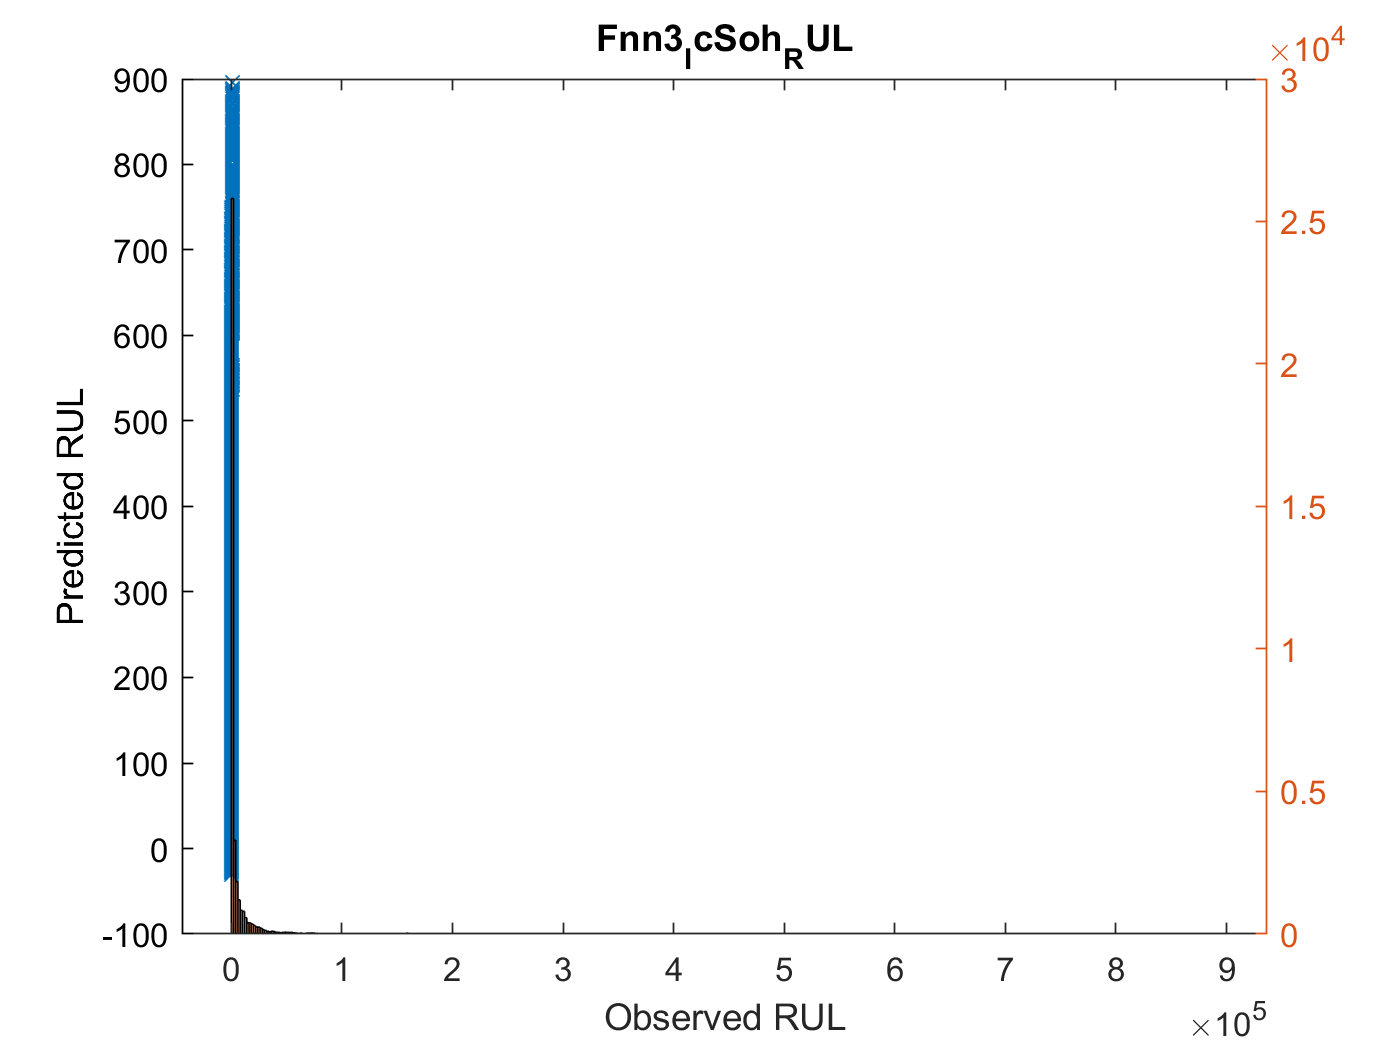

(Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2;   % Squared Error
histogram((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2)

mean((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2);   % Mean Squared Error
RMSE_trainValid_VdSohRul = sqrt(mean((Y_trainValid_RUL - Yfit_trainValid_VdSohRul).^2))  % Root Mean Squared Error

RMSE_trainValid_VdSohRul = 77.6128


RMSE_test_VdSohRul = sqrt(mean((Y_test_RUL - Yfit_test_VdSohRul).^2))

RMSE_test_VdSohRul = 86.2815

Y_test_RUL - Yfit_test_VdSohRul

ans = 4488×1
  -63.2198
  -59.1138
  -57.7013
  -56.0307
  -55.5510
  -55.0786
  -54.6016
  -55.3190
  -53.8937
  -53.7036


Y_test_diff_VdSohRul = horzcat(Y_test_RUL,(Y_test_RUL-Yfit_test_VdSohRul))

Y_test_diff_VdSohRul = 4488×2
  316.0000  -63.2198
  315.0000  -59.1138
  314.0000  -57.7013
  313.0000  -56.0307
  312.0000  -55.5510
  311.0000  -55.0786
  310.0000  -54.6016
  309.0000  -55.3190
  308.0000  -53.8937
  307.0000  -53.7036


Y_test_diff_percentage_VdSohRul = abs(Y_test_RUL-Yfit_test_VdSohRul)./Y_test_RUL.*100

Y_test_diff_percentage_VdSohRul = 4488×1
   20.0063
   18.7663
   18.3762
   17.9012
   17.8048
   17.7102
   17.6134
   17.9026
   17.4980
   17.4930


Y_test_diff_percentage_avg_VdSohRul = sum(Y_test_diff_percentage_VdSohRul)/length(Y_test_diff_percentage_VdSohRul)

Y_test_diff_percentage_avg_VdSohRul = 24.9449

Y_trainValid_diff_VdSohRul = horzcat(Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul))

Y_trainValid_diff_VdSohRul = 38367×2
  428.0000   28.3947
  427.0000   26.8607
  426.0000   29.7903
  425.0000   29.0654
  424.0000   25.0317
  423.0000   25.6996
  422.0000   29.3481
  421.0000   28.4203
  420.0000   29.5325
  419.0000   29.7303


Y_trainValid_diff_percentage_VdSohRul = abs(Y_trainValid_RUL-Yfit_trainValid_VdSohRul)./Y_trainValid_RUL.*100

Y_trainValid_diff_percentage_VdSohRul = 38367×1
    6.6343
    6.2906
    6.9930
    6.8389
    5.9037
    6.0756
    6.9545
    6.7507
    7.0316
    7.0955


Y_trainValid_diff_percentage_avg_VdSohRul = sum(Y_trainValid_diff_percentage_VdSohRul)/length(Y_trainValid_diff_percentage_VdSohRul)

Y_trainValid_diff_percentage_avg_VdSohRul = 28.6412

num = 1:length(Y_trainValid_RUL);


result = horzcat(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul),Y_trainValid_diff_percentage_VdSohRul);
result % 배터리 번호 / SOH 관찰값 / 오차 / 오차 퍼센티지 

result = 38367×4
    1.0000  428.0000   28.3947    6.6343
    2.0000  427.0000   26.8607    6.2906
    3.0000  426.0000   29.7903    6.9930
    4.0000  425.0000   29.0654    6.8389
    5.0000  424.0000   25.0317    5.9037
    6.0000  423.0000   25.6996    6.0756
    7.0000  422.0000   29.3481    6.9545
    8.0000  421.0000   28.4203    6.7507
    9.0000  420.0000   29.5325    7.0316
   10.0000  419.0000   29.7303    7.0955


result_mdl_Fnn3_VdSohRul = table(num',Y_trainValid_RUL,(Y_trainValid_RUL-Yfit_trainValid_VdSohRul),Y_trainValid_diff_percentage_VdSohRul);
result_mdl_Fnn3_VdSohRul.Properties.VariableNames = {'bat num','RUL','Error','APE'};
result_mdl_Fnn3_VdSohRul

result_mdl_Fnn3_VdSohRul = 38367×4 table
    bat num    RUL    Error      APE  
    _______    ___    ______    ______

       1       428    28.395    6.6343
       2       427    26.861    6.2906
       3       426     29.79     6.993
       4       425    29.065    6.8389
       5       424    25.032    5.9037
       6       423      25.7    6.0756
       7       422    29.348    6.9545
       8       421     28.42    6.7507
       9       420    29.533    7.0316
      10       419     29.73    7.0955
      11       418    27.703    6.6274
      12       417    22.589     5.417
      13       416    22.613    5.4359
      14       415    25.547     6.156
      15       414    25.808    6.2339
      16       413    23.718    5.7428


result_mdl_Fnn3_VdSohRul_summary = table(RMSE_test_VdSohRul,Y_trainValid_diff_percentage_avg_VdSohRul);
result_mdl_Fnn3_VdSohRul_summary.Properties.VariableNames = {'RMSE','MAPE'};
result_mdl_Fnn3_VdSohRul_summary 

result_mdl_Fnn3_VdSohRul_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    86.282    28.641



Fnn3_VdSohRul_rmse = RMSE_test_VdSohRul

Fnn3_VdSohRul_rmse = 86.2815

Fnn3_VdSohRul_mape = Y_trainValid_diff_percentage_avg_VdSohRul

Fnn3_VdSohRul_mape = 28.6412

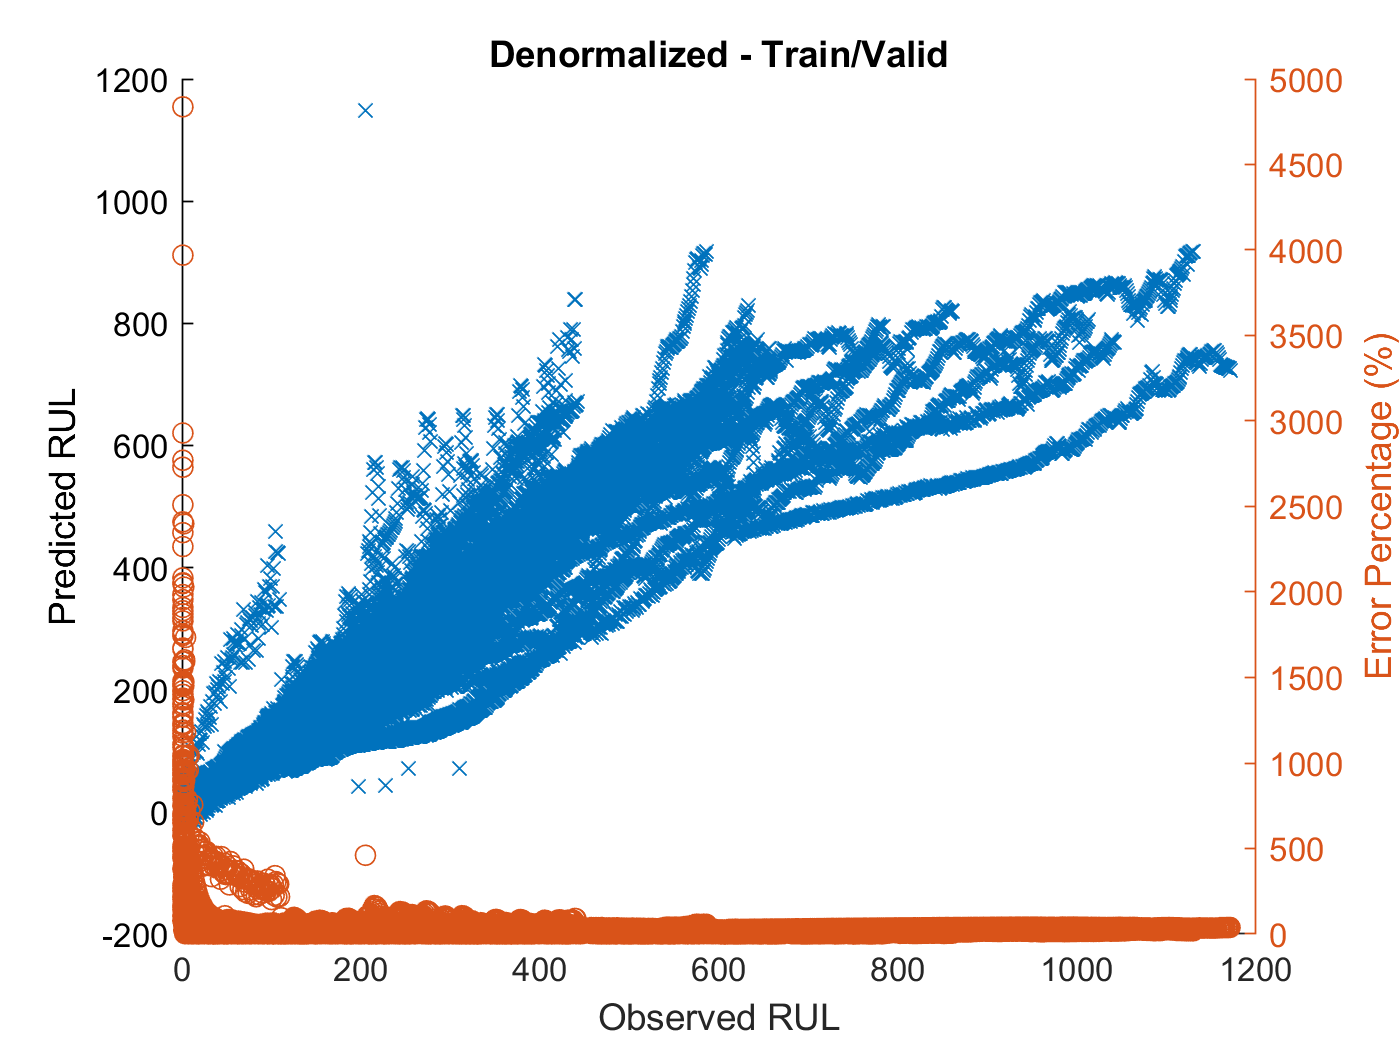


figure
hold on
plot(Y_trainValid_RUL,Yfit_trainValid_VdSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_trainValid_RUL,Y_trainValid_diff_percentage_VdSohRul,'o');

hold off
title 'Denormalized - Train/Valid'

RMSE_test_VdSohRul

RMSE_test_VdSohRul = 86.2815

Y_trainValid_diff_percentage_avg_VdSohRul

Y_trainValid_diff_percentage_avg_VdSohRul = 28.6412

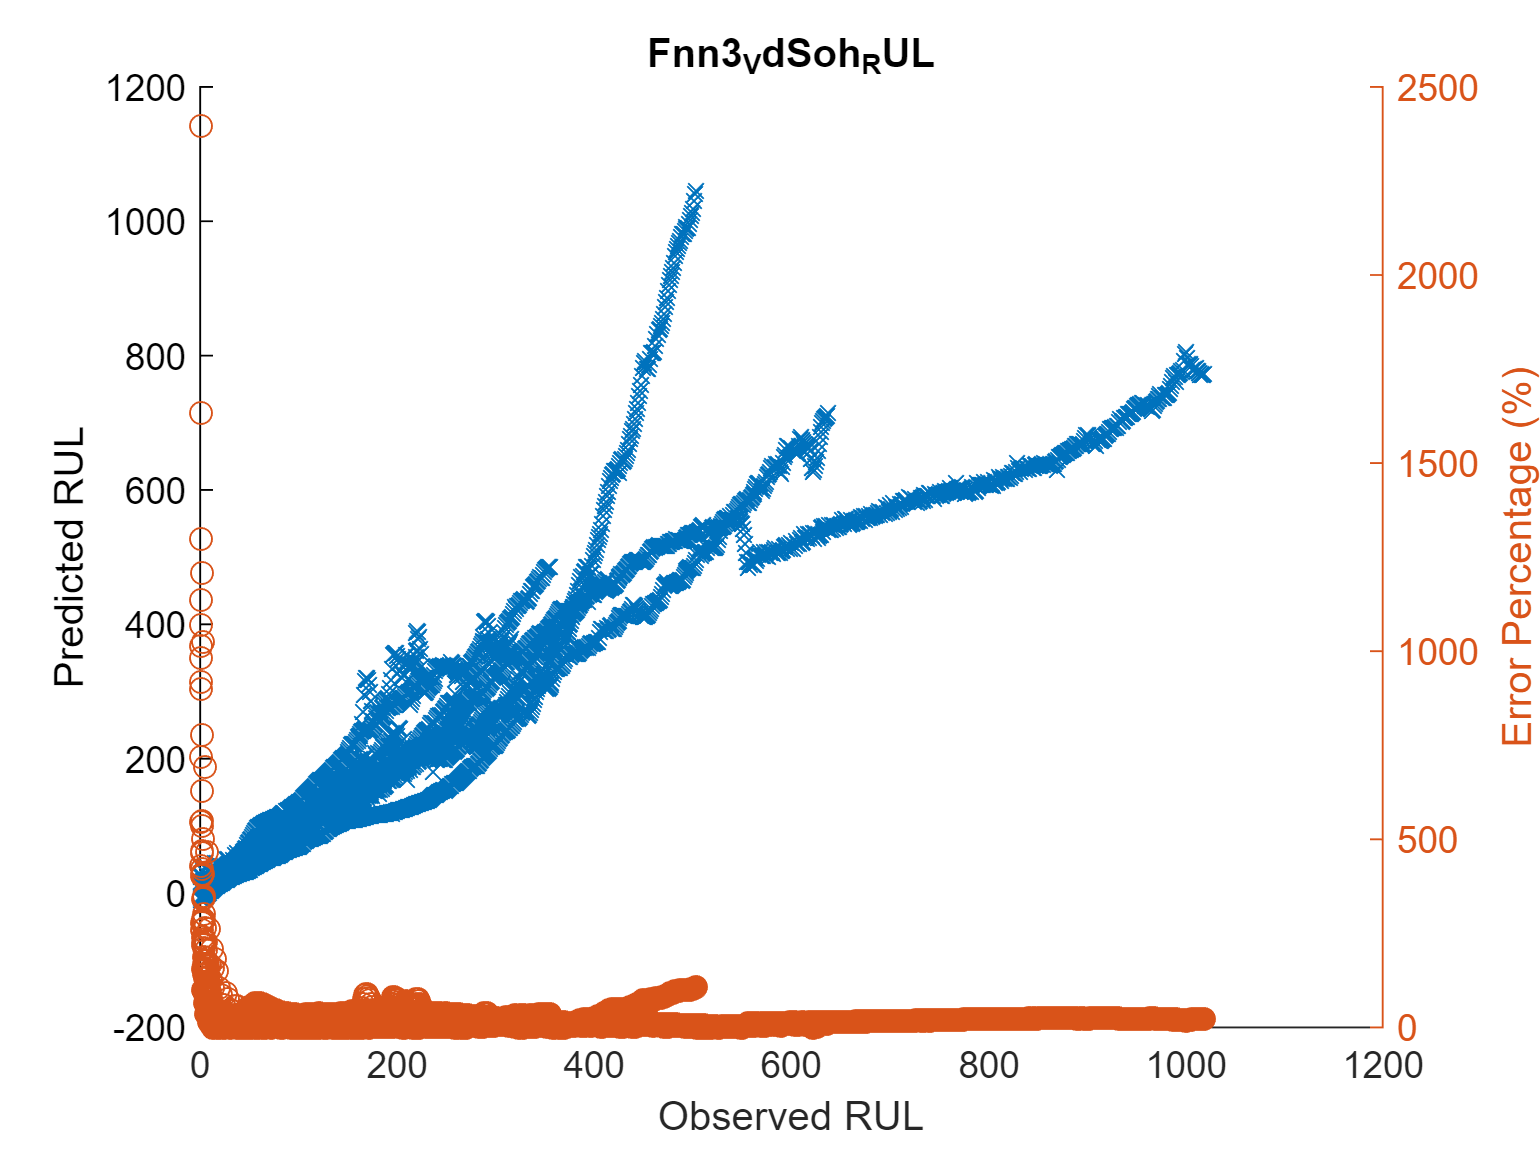


figure
hold on
plot(Y_test_RUL,Yfit_test_VdSohRul,'x')
xlabel("Observed RUL")
ylabel("Predicted RUL")
%xlim([0 1.2]), ylim([0 1.2])

yyaxis right
ylabel('Error Percentage (%)')
plot(Y_test_RUL,Y_test_diff_percentage_VdSohRul,'o');

hold off
title 'Fnn3_VdSoh_RUL'

# 실험결과 

result_mdl_Linear_IcSohRul

result_mdl_Linear_IcSohRul = 38367×4 table
    bat num    RUL     Error      APE  
    _______    ___    _______    ______

       1       428    -35.128    8.2074
       2       427    -121.03    28.343
       3       426    -122.47     28.75
       4       425    -71.886    16.914
       5       424     -66.44     15.67
       6       423    -110.11    26.032
       7       422     -56.38     13.36
       8       421    -107.02     25.42
       9       420    -28.297    6.7373
      10       419    -25.764     6.149
      11       418    -64.445    15.418
      12       417    -103.58    24.838
      13       416    -106.01    25.482
      14       415    -38.565    9.2928
      15       414    -27.999    6.7631
      16       413    -99.132    24.003


result_mdl_Linear_VdSohRul

result_mdl_Linear_VdSohRul = 38367×4 table
    bat num    RUL     Error      APE  
    _______    ___    _______    ______

       1       428    -29.516    6.8963
       2       427    -39.459    9.2409
       3       426    -33.129    7.7768
       4       425      -27.9    6.5648
       5       424    -36.165    8.5295
       6       423    -36.867    8.7156
       7       422    -28.884    6.8445
       8       421    -35.178    8.3558
       9       420    -20.745    4.9393
      10       419     -19.57    4.6706
      11       418    -33.531    8.0217
      12       417    -36.287    8.7019
      13       416    -38.301     9.207
      14       415      -35.4    8.5301
      15       414    -28.206    6.8131
      16       413    -37.823    9.1581


result_mdl_Fnn_IcSohRul

result_mdl_Fnn_IcSohRul = 38367×4 table
    bat num    RUL     Error      APE  
    _______    ___    _______    ______

       1       428    -35.128    8.2074
       2       427    -121.03    28.343
       3       426    -122.47     28.75
       4       425    -71.886    16.914
       5       424     -66.44     15.67
       6       423    -110.11    26.032
       7       422     -56.38     13.36
       8       421    -107.02     25.42
       9       420    -28.297    6.7373
      10       419    -25.764     6.149
      11       418    -64.445    15.418
      12       417    -103.58    24.838
      13       416    -106.01    25.482
      14       415    -38.565    9.2928
      15       414    -27.999    6.7631
      16       413    -99.132    24.003


result_mdl_Fnn_VdSohRul

result_mdl_Fnn_VdSohRul = 38367×4 table
    bat num    RUL     Error      APE  
    _______    ___    _______    ______

       1       428    -48.409    11.311
       2       427    -48.674    11.399
       3       426    -46.468    10.908
       4       425    -45.448    10.694
       5       424     -51.41    12.125
       6       423    -50.784    12.006
       7       422    -46.771    11.083
       8       421    -45.915    10.906
       9       420    -44.169    10.517
      10       419    -44.717    10.672
      11       418    -46.924    11.226
      12       417    -53.995    12.948
      13       416    -51.129    12.291
      14       415    -50.438    12.154
      15       414    -48.757    11.777
      16       413    -50.194    12.154


result_mdl_Fnn3_IcSohRul

result_mdl_Fnn3_IcSohRul = 38367×4 table
    bat num    RUL     Error      APE  
    _______    ___    _______    ______

       1       428    -85.934    20.078
       2       427    -265.98    62.289
       3       426    -266.17     62.48
       4       425    -167.84    39.493
       5       424     -155.7    36.723
       6       423    -253.29     59.88
       7       422    -138.23    32.755
       8       421    -248.25    58.966
       9       420     -90.06    21.443
      10       419    -88.157     21.04
      11       418    -165.68    39.637
      12       417    -246.74    59.169
      13       416    -250.65    60.251
      14       415    -116.19    27.998
      15       414    -95.407    23.045
      16       413    -242.11    58.621


result_mdl_Fnn3_VdSohRul

result_mdl_Fnn3_VdSohRul = 38367×4 table
    bat num    RUL    Error      APE  
    _______    ___    ______    ______

       1       428    28.395    6.6343
       2       427    26.861    6.2906
       3       426     29.79     6.993
       4       425    29.065    6.8389
       5       424    25.032    5.9037
       6       423      25.7    6.0756
       7       422    29.348    6.9545
       8       421     28.42    6.7507
       9       420    29.533    7.0316
      10       419     29.73    7.0955
      11       418    27.703    6.6274
      12       417    22.589     5.417
      13       416    22.613    5.4359
      14       415    25.547     6.156
      15       414    25.808    6.2339
      16       413    23.718    5.7428



result_mdl_Linear_IcSohRul_summary

result_mdl_Linear_IcSohRul_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    121.67    90.796


result_mdl_Linear_VdSohRul_summary

result_mdl_Linear_VdSohRul_summary = 1×2 table
    RMSE      MAPE 
    _____    ______

    90.07    62.983


result_mdl_Fnn_IcSohRul_summary

result_mdl_Fnn_IcSohRul_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    94.271    90.796


result_mdl_Fnn_VdSohRul_summary

result_mdl_Fnn_VdSohRul_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    95.354    69.161


result_mdl_Fnn3_IcSohRul_summary

result_mdl_Fnn3_IcSohRul_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    97.631    44.153


result_mdl_Fnn3_VdSohRul_summary

result_mdl_Fnn3_VdSohRul_summary = 1×2 table
     RMSE      MAPE 
    ______    ______

    86.282    28.641




rmse_list = [ ... 
    Linear_IcSohRul_rmse ; ...
    Linear_VdSohRul_rmse ; ...
    Fnn_IcSohRul_rmse ; ...
    Fnn_VdSohRul_rmse ; ...
    Fnn3_IcSohRul_rmse ; ...
    Fnn3_VdSohRul_rmse ];

mape_list = [ ... 
    Linear_IcSohRul_mape ; ...
    Linear_VdSohRul_mape ; ...
    Fnn_IcSohRul_mape ; ...
    Fnn_VdSohRul_mape ; ...
    Fnn3_IcSohRul_mape ; ...
    Fnn3_VdSohRul_mape ];
	
model_list = [ ... 
    "Linear_IcSoh_RUL" ; ...
    "Linear_VdSoh_RUL" ; ...
    "Fnn_IcSoh_RUL" ; ...
    "Fnn_VdSoh_RUL" ; ...
    "Fnn3_IcSoh_RUL" ; ...
    "Fnn3_VdSoh_RUL" ];
	
	
	
RowNames = [ ... 
    'Linear_IcSoh_RUL' , ...
    'Linear_VdSoh_RUL' , ...
    'Fnn_IcSoh_RUL' , ...
    'Fnn_VdSoh_RUL' , ...
    'Fnn3_IcSoh_RUL' , ...
    'Fnn3_VdSoh_RUL' ];
VariableNames = {'Model','RMSE','MAPE'}

VariableNames = 1×3 cell array
    {'Model'}    {'RMSE'}    {'MAPE'}




result_SOH_RUL = table( model_list, rmse_list , mape_list , 'VariableNames',VariableNames);
result_SOH_RUL.Properties.Description = 'Test Result : predict RUL with SOH';
result_SOH_RUL.Properties

ans =   TableProperties with properties:

             Description: 'Test Result : predict RUL with SOH'
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Model'  'RMSE'  'MAPE'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


result_SOH_RUL.Properties.RowNames = model_list;
result_SOH_RUL

result_SOH_RUL = 6×3 table
                              Model            RMSE      MAPE 
                        __________________    ______    ______

    Linear_IcSoh_RUL    "Linear_IcSoh_RUL"    121.67    90.796
    Linear_VdSoh_RUL    "Linear_VdSoh_RUL"     90.07    62.983
    Fnn_IcSoh_RUL       "Fnn_IcSoh_RUL"       94.271    90.796
    Fnn_VdSoh_RUL       "Fnn_VdSoh_RUL"       95.354    69.161
    Fnn3_IcSoh_RUL      "Fnn3_IcSoh_RUL"      94.271    90.796
    Fnn3_VdSoh_RUL      "Fnn3_VdSoh_RUL"      86.282    28.641


if save_model
save('ryan4_model_SOH_RUL.mat','result_mdl_Linear_IcSohRul' )
save('ryan4_model_SOH_RUL.mat','result_mdl_Linear_VdSohRul' )
save('ryan4_model_SOH_RUL.mat','result_mdl_Fnn_IcSohRul' )
save('ryan4_model_SOH_RUL.mat','result_mdl_Fnn_VdSohRul' )
save('ryan4_model_SOH_RUL.mat','result_mdl_Fnn3_IcSohRul' )
save('ryan4_model_SOH_RUL.mat','result_mdl_Fnn3_VdSohRul' )

save('ryan4_model_SOH_RUL.mat','result_mdl_Linear_IcSohRul_summary' )
save('ryan4_model_SOH_RUL.mat','result_mdl_Linear_VdSohRul_summary' )
save('ryan4_model_SOH_RUL.mat','result_mdl_Fnn_IcSohRul_summary' )
save('ryan4_model_SOH_RUL.mat','result_mdl_Fnn_VdSohRul_summary' )
save('ryan4_model_SOH_RUL.mat','result_mdl_Fnn3_IcSohRul_summary' )
save('ryan4_model_SOH_RUL.mat','result_mdl_Fnn3_VdSohRul_summary' )
end 

% https://kr.mathworks.com/help/matlab/data_analysis/linear-regression.html
% https://kr.mathworks.com/matlabcentral/answers/368689-how-to-define-a-custom-equation-in-fitlm-function-for-linear-regression